# Semantic Segmentation of Multispectral Images Using Deep Learning

This example shows how to train a U-Net convolutional neural network to perform semantic segmentation of a multispectral image with seven channels: three color channels, three near-infrared channels, and a mask.

The example shows how to train a U-Net network and also provides a pretrained U-Net network. If you choose to train the U-Net network, use of a CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended (requires Parallel Computing Toolbox™).

## Introduction

Semantic segmentation involves labeling each pixel in an image with a class. One application of semantic segmentation is tracking deforestation, which is the change in forest cover over time. Environmental agencies track deforestation to assess and quantify the environmental and ecological health of a region.

Deep-learning-based semantic segmentation can yield a precise measurement of vegetation cover from high-resolution aerial photographs. One challenge is differentiating classes with similar visual characteristics, such as trying to classify a green pixel as grass, shrubbery, or tree. To increase classification accuracy, some data sets contain multispectral images that provide additional information about each pixel. For example, the Hamlin Beach State Park data set supplements the color images with near-infrared channels that provide a clearer separation of the classes.

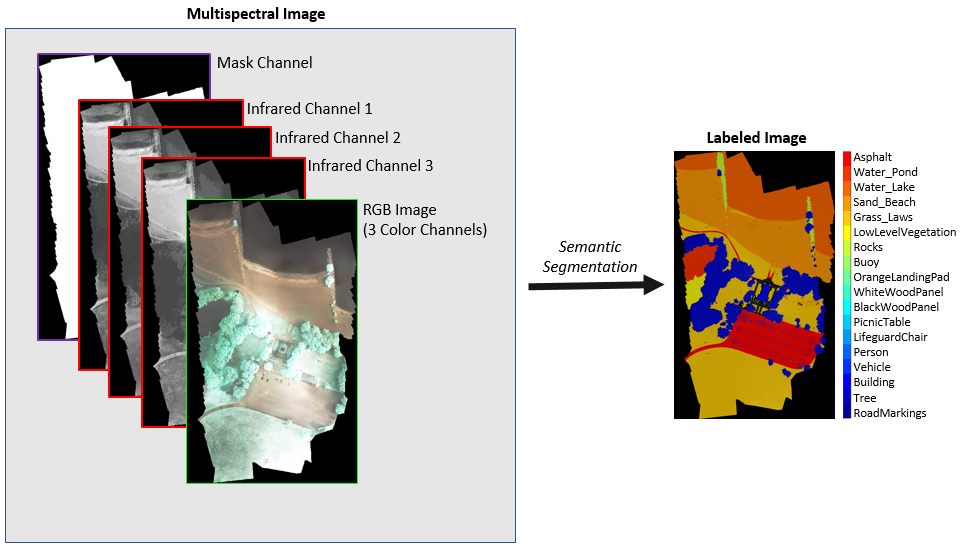

This example shows how to use deep-learning-based semantic segmentation techniques to calculate the percentage vegetation cover in a region from a set of multispectral images.

## Check required files and products

At first it looks convenient to run a check of all the scripts, functions and products (as in toolboxes) that are needed for the following program to run properly and without errors. By usign the function `requiredFilesAndProducts`, two outputs are obtained, one for files, **fList**, and one for products, **pList**. The rest of the section are just some manipulations to the output so they can be easier understood by the user.

[fList,pList] = matlab.codetools.requiredFilesAndProducts(...
    'G_SemanticSegmentation.mlx');
{pList.Name}

ans = 1×4 cell array
    {'MATLAB'}    {'Deep Learning Toolbox'}    {'Image Processing Toolbox'}    {'Computer Vision Toolbox'}


for i= 1:length(fList)
    t = strsplit(fList{i},pwd) ;
%     disp(t{2})
end

Once we make sure all files and products are in order, we can continue with the execution.

## Fast execution

If everything is properly set up and want to

createDatabase = true;
doTraining = true;

Otherwise, the whole process can be followed below.

## Stored data

Data used in this program to make up the database comes straight from **El Simulador** as .bin files. They'll later be read, decoded and interpreted but for now let's just define the folders where they are located.

sensors = ["LWIR", "MWIR", "VIS"];

frameRawFolder = './frames_raw/';


In addition, we'll define which files will conform the training data and the test data by noting in which folders they are stored.

frameRawTrainFolder = './frames_raw/Dubai';
frameRawTestFolder = './frames_raw/Kremlin';

We'll also define the colormap used for the segmentation which is the same as the one used by the finder.

global map
map = [0 0 0.5          % SEA
    0.012 0.161 1.0     % WATER
    0.021 0.021 0.021   % ROADS
    0 0.7 0             % VEGETATION
    1 0.03 0            % BUILDINGS
    0.5 0.4 0           % TERRAIN
    ];

## Previous configurations

Since all the pictures used in the database are generated by **El Simulador** and it also simulates the optics of a real camera, it is necessary to point out the camera parameters it's going to simulate, so we can later undo the geometric deformation. 

### Camera's parameters

All sensors are configured exactly the same way, so the same is seen by all three, which avoids the problem of having to sync what's seen by each sensor. 

% Parameters
global res
res = [1024 1280];          %VxH
pitch = 15e-6;              %in m
focalDist = 21.87e-3;       %in m
Alig = 0;                   %in deg
t_int = 10;                 %in ms

% Calculations
IFOV = pitch/focalDist; %F-Theta projection
FOV = (res.*IFOV)*180/pi;

infoPrinter(Alig,FOV,pitch,focalDist,res,t_int);


--- Sensor data ---
Alignment SENSOR-PLATFORM: 0 deg
FOV_H: 40.240657 deg / FOV_V: 50.300822 deg
Projection: f-Theta
Pitch: 15.000000 um
Focal distance: 21.870000 mm
Resolution (VxH): [1024 1280] px
Initial integration time: 10 ms


## Database generation

Teh database will be generated by **El Simulador **as previously stated, which outputs raw frames as `.bin` files, with raw meaning unprocessed. These raw frames contain the information needed but first of all, they are codified as .bin files, and, since it simulates real optics, these frames will experiment color and geometric deformations that need to be corrected for the proper training of the CNN. 

The decoding of bin files will be dealt with later on, so the deformations will be corrected in the first place

### Vignetting correction

The shape of the lens produces a shadow over the sensor which results in a vignetting effect in the generated image. [...] To correct this, a calibration image of a flat reflective surface is generated and then, some coefficientes of adjustment are extracted. These calibration raw frames are stored under a folder called `/calibracionNarcisus`

tam = 20;

for k = 1:3
    if sensors(k) == "LWIR"
        imagenCalibracion = LeerFramesIR('calibracionNarcisus/Frame_NarcisusLWIR.bin');
        calibLWIR = imagenCalibracion;
%         imshow(imagenCalibracion,[]);
    elseif sensors(k) == "MWIR"
        imagenCalibracion = LeerFramesIR('calibracionNarcisus/Frame_NarcisusMWIR.bin');
        calibMWIR = imagenCalibracion;
%         imshow(imagenCalibracion,[]);
    elseif sensors(k) == "VIS"
        imagenCalibracion_R = LeerFramesIR('calibracionNarcisus/Frame_NarcisusVIS_R.bin');
        imagenCalibracion_G = LeerFramesIR('calibracionNarcisus/Frame_NarcisusVIS_G.bin');
        imagenCalibracion_B = LeerFramesIR('calibracionNarcisus/Frame_NarcisusVIS_B.bin');
        imagenCalibracion(:,:,1) = imagenCalibracion_R;
        imagenCalibracion(:,:,2) = imagenCalibracion_G;
        imagenCalibracion(:,:,3) = imagenCalibracion_B;
        calibVIS = imagenCalibracion;
%         imshow(uint8(imagenCalibracion));
    end
    
    centro = size(imagenCalibracion(:,:,1))/2;
    centro_izq = centro - tam/2 + 1;
    centro_der = centro + tam/2;
    
    cos4theta = imagenCalibracion/mean(mean(imagenCalibracion(centro_izq(1):centro_der(1),centro_izq(2):centro_der(2))));

    % Debido al ruido, puede haber coeficientes que sean mayores que 1, así que se fijan a 1
    cos4theta(cos4theta>1) = 1 ; 

    % Las imágenes de compensación serían
    if sensors(k) == "LWIR"
        global Coef_NarcisusLWIR
        Coef_NarcisusLWIR = 1./cos4theta;    
    elseif sensors(k) == "MWIR"
        global Coef_NarcisusMWIR
        Coef_NarcisusMWIR = 1./cos4theta;    
    elseif sensors(k) == "VIS"    
        global Coef_NarcisusVIS
        Coef_NarcisusVIS = 1./cos4theta;    
    end
end

### Geometric distorsion correction

The shape of the lens also induces a geometric aberration, which is also not desired for the training. In order to correct the geometric distorsion there are two different ways.

- The first one involves a lot of math and heavy algorithms, by applying to each pixel the exact geometric transformation it needs, based on the lens parameters and the type of projection; f-Theta in this case.

- The second one is much less computational intensive and it delivers results that are hard to distinguish from the ones extracted from the first method, and most importantly, it has been tested to work well enough for the finder algorithm to find it. This method requires to obtain some calibration images which cosist basically of a checkerboard, and from then, we are able to extract some camera features and calculate and apply the estimated geometric transform. This method's inspiration can be found in Matlab's documentation and it's referenced below.

method = 1

method = 1

 The calibration frames consist on the generation of a chess board that varies its distance (and angle) to the camera. So let's begin by reading the id file and the raw frame to produce a colored chess picture that will be passed onto the calibration functions.  

tic;
chessFrames = fileSorter('./lens_correction/ids');
ficheroIDs = './lens_correction/IdentificadoresBlancosEscenario.xml';
tagsChess = xmlReader(ficheroIDs); 

Define a chess color map to color the obtained images.

chessmap = [
    0 0 0
    1 1 1
    0 0 0.5
    ];

Read and color frames obtained

for i = 1:length(chessFrames)/2
    frameFile = fullfile(chessFrames(i).folder,chessFrames(i).name);
    frame = LeerFramesIDs(frameFile); 
    frame = frame(:,:,1);
    frame(frame==-1)=3;
    frame(frame==3)=3;
    frame(frame==tagsChess('blancoChess'))=1;
    frame(frame==tagsChess('negroChess'))=2;
    
    labelledImage = labeloverlay(ones(res),frame,'Transparency', 0,'Colormap',chessmap);
    imwrite(labelledImage, sprintf('./lens_correction/lens_correction_%02d.png',i))
end

Create a set of calibration images.

images = imageDatastore('./lens_correction/');

Detect calibration pattern.

[imagePoints,boardSize] = detectCheckerboardPoints(images.Files);

Generate world coordinates of the corners of the squares. The square size is in millimeters.

squareSize = 29;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

Calibrate the camera.

I = readimage(images,13); 
imageSize = [size(I,1),size(I,2)];
global cameraParams
cameraParams = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);
toc;

Elapsed time is 90.096919 seconds.


Remove lens distortion and display results. 

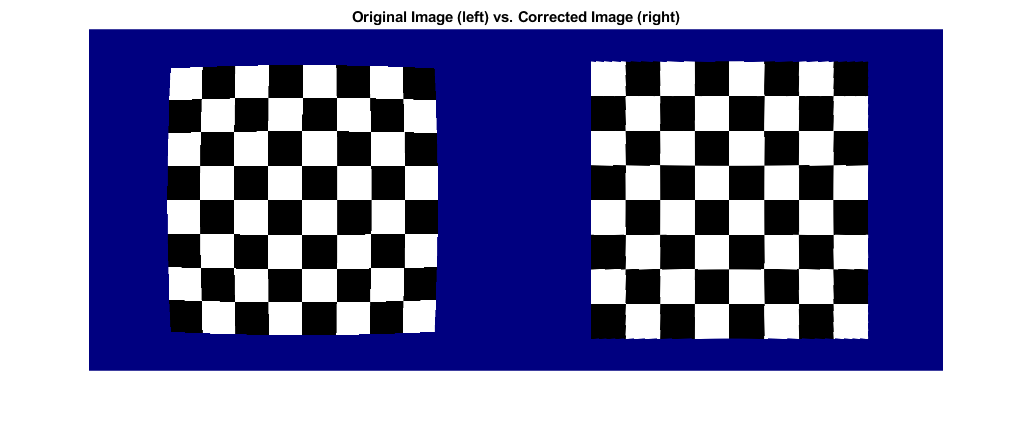

I = images.readimage(randi([1 length(chessFrames)/2]));
J1 = undistortImage(I,cameraParams);
figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)');

% J2 = undistortImage(I,cameraParams,'OutputView','full');
% figure;
% imshow(J2);
% title('Full Output View');


In order to get a better overview of this method, let's compare how the same picture would look like with the corrected deformation using the second method.

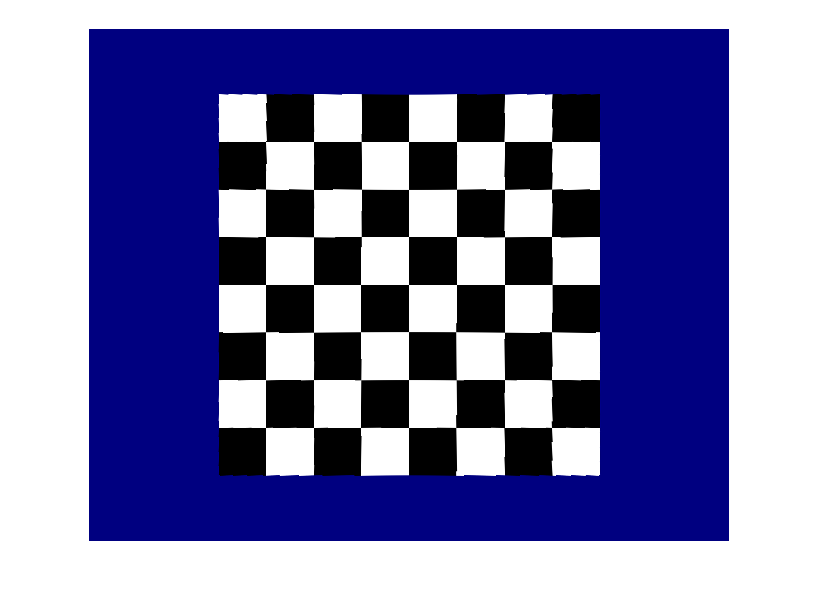

comparison = false;
if comparison
    tic;
    pitch = 15e-6;              %in m
    focalDist = 21.87e-3;       %in m
    Alig = 0;                   %in deg
    t_int = 10;                 %in ms

    % Calculations
    IFOV = pitch/focalDist; %F-Theta projection
    FOV = (res.*IFOV)*180/pi;
    load Kernel_Interp_bicubica.mat
    distFocalS1 = focalDist*10^6; %in um
    distFocalS2 = distFocalS1; %in um
    PitchS1 = pitch*10^3; %in mm
    PitchS2 = PitchS1; %in mm
    IOPTyawS1 = Alig;  %in rad
    IOPTyawS2 = Alig;  %in rad
    IFOVOut = PitchS1/distFocalS1*1000;
    ModoProyeccion = true; %False -> Proyeccion Detector ; True -> Proyeccion Imagen

    frameZ = PanoramicVIS(1,res(1),res(2),I,I, distFocalS1,distFocalS2,...
        PitchS1, PitchS2, IOPTyawS1, IOPTyawS2,IFOVOut,ModoProyeccion,...
        Tabla1_Interp_bicubica,Tabla2_Interp_bicubica);

    imshow(frameZ);
    save frameZ.mat frameZ
    toc;
else
    load("frameZ.mat")
    imshow(frameZ);    
end

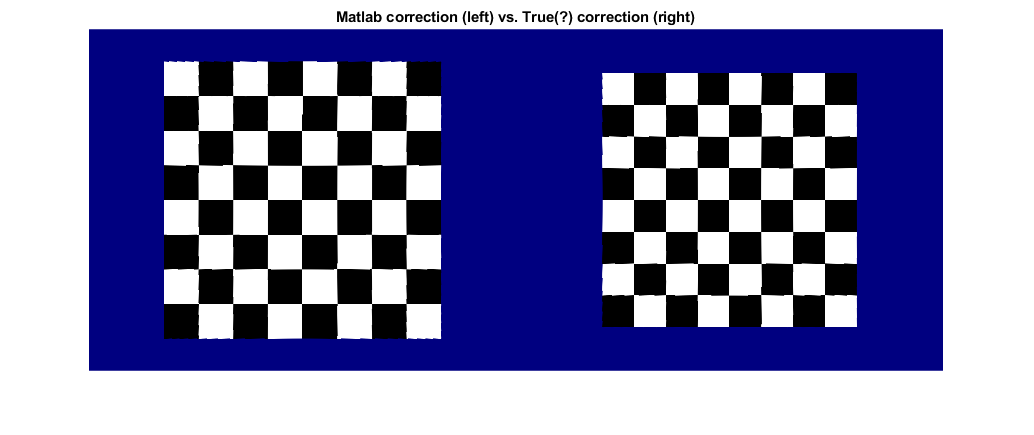

figure; imshowpair(J1,frameZ,'montage');
title('Matlab correction (left) vs. True(?) correction (right)');

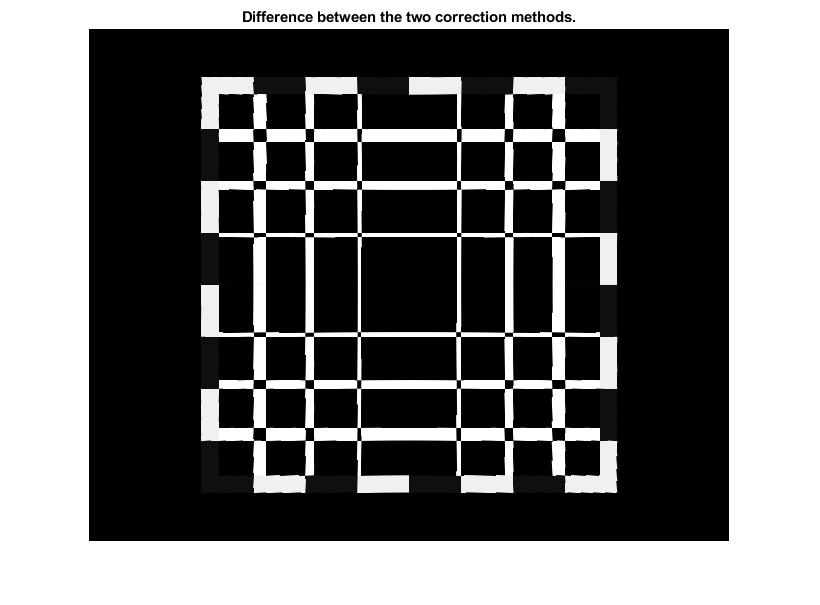

figure; imshowpair(J1,frameZ,'diff');
title('Difference between the two correction methods.')

### Read frames and create Database

Begin by defining some basic parameters for reading the frames such as the sensors' names, resolution or output folders.

frameRawFolder = './frames_raw/Dubai';
frameFolderOutput = './frames/';
databaseFolder = './frames_database/';

If the variable `createDatabase` is true, this code will read one by one all the `.bin` files stored in the folder specified by `frameRawFolder` and apply the geometric and vignetting corrections calculated previously and will save them to the folders specified by `frameFolderOutput`, as image files, and `databaseFolder`, where they'd be stored as a `.mat` file containing all 5 layers of information and a ground truth file for each frame, ready to be fed to the network trainer. Turn `createDatabase` to false if there's already a database created previously or if you don't want to create one.

createDatabase = true;
if createDatabase
    n = dataPacker(0,frameRawFolder,databaseFolder,frameFolderOutput);
end

439 frames packed
Elapsed time is 1032.465378 seconds.


The labeled images contain the ground truth data for the segmentation, with each pixel assigned to one of the 6 classes. Create a vector of class names.

classNames = [ "sea","water","roads","vegetation","buildings","terrain"]; 

Display which class is associated with each number in the labelled images.

for i= 1:numel(classNames)
    fprintf('%i %s\n',i, classNames(i))

end

1 sea
2 water
3 roads
4 vegetation
5 buildings
6 terrain


## Create Random Patch Extraction Datastore for Training

Use a random patch extraction datastore to feed the training data to the network. This datastore extracts multiple corresponding random patches from an image datastore and pixel label datastore that contain ground truth images and pixel label data. Patching is a common technique to prevent running out of memory for large images and to effectively increase the amount of available training data.

Begin by storing the training images from `'frames_database'` in an [`imageDatastore`](docid:matlab_ref#butueui-1). Because the MAT file format is a nonstandard image format, you must use a MAT file reader to enable reading the image data. You can use the helper MAT file reader, `matReader`, that extracts the first six channels from the training data and omits the last channel containing the mask. This function is attached to the example as a supporting file.

imds = imageDatastore('./frames_database/frames/','FileExtensions','.mat','ReadFcn',@G_matReader);

Create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) to store the label patches containing the 18 labeled regions.

pixelLabelIds = 1:numel(classNames);
pxds = pixelLabelDatastore('./frames_database/gtruth/',classNames,pixelLabelIds, 'FileExtensions','.png');%'.mat');

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) from the image datastore and the pixel label datastore. Each mini-batch contains 16 patches of size 256-by-256 pixels. One thousand mini-batches are extracted at each iteration of the epoch.

augmenter = imageDataAugmenter('RandRotation',[0 90],'RandXReflection',true);

dsTrain = randomPatchExtractionDatastore(imds,pxds,[256,256],...
    'DispatchInBackground',false,...
    'PatchesPerImage',8,...
    'DataAugmentation',augmenter);
%    'PatchesPerImage',16000,...
%     'DispatchInBackground',true,...
%     'DataAugmentation',augmenter);


The random patch extraction datastore `dsTrain` provides mini-batches of data to the network at each iteration of the epoch. Preview the datastore to explore the data.

inputBatch = preview(dsTrain);
disp(inputBatch)

        InputImage        ResponsePixelLabelImage
    __________________    _______________________

    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 
    {256×256×5 uint16}     {256×256 categorical} 



inputs = inputBatch.InputImage;
responses = inputBatch.ResponsePixelLabelImage;

## Create U-Net Network Layers

This example uses a variation of the U-Net network. In U-Net, the initial series of convolutional layers are interspersed with max pooling layers, successively decreasing the resolution of the input image. These layers are followed by a series of convolutional layers interspersed with upsampling operators, successively increasing the resolution of the input image [2]. The name U-Net comes from the fact that the network can be drawn with a symmetric shape like the letter U.

This example modifies the U-Net to use zero-padding in the convolutions, so that the input and the output to the convolutions have the same size. Use the helper function, `createUnet`, to create a U-Net with a few preselected hyperparameters. This function is attached as a supporting file to the example.

inputTileSize = size(inputs{1,1});%[256,256,6];
lgraph = G_createUnet(inputTileSize);
disp(lgraph.Layers)

  70×1 Layer array with layers:

     1   'ImageInputLayer'                        Image Input                  256×256×5 images with 'zerocenter' normalization
     2   'Encoder-Section-1-Conv-1'               Convolution                  64 3×3×5 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'Encoder-Section-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Section-1-Conv-2'               Convolution                  64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'Encoder-Section-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Section-1-MaxPool'              Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Section-2-Conv-1'               Convolution                  128 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'Encoder

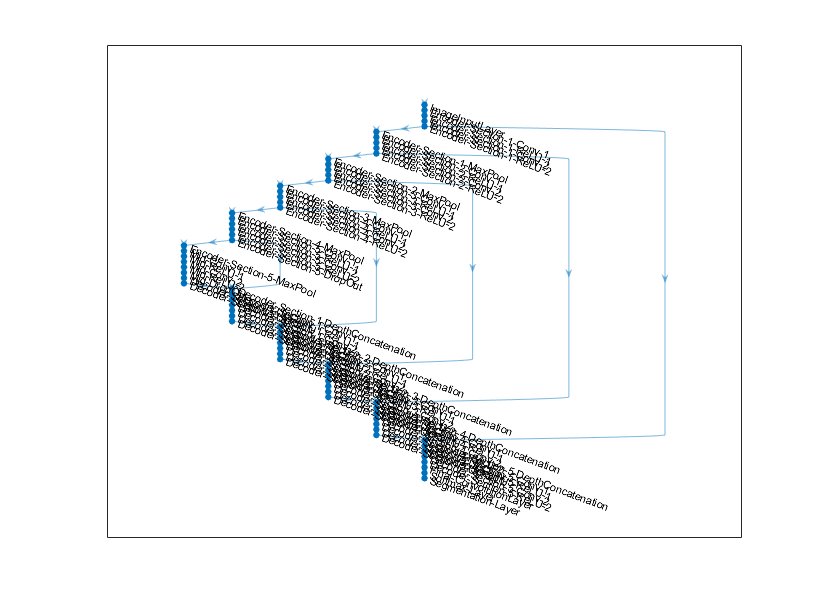

plot(lgraph)

## Select Training Options

Train the network using stochastic gradient descent with momentum (SGDM) optimization. Specify the hyperparameter settings for SDGM by using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function.

Training a deep network is time-consuming. Accelerate the training by specifying a high learning rate. However, this can cause the gradients of the network to explode or grow uncontrollably, preventing the network from training successfully. To keep the gradients in a meaningful range, enable gradient clipping by specifying `'GradientThreshold'` as `0.05`, and specify `'GradientThresholdMethod'` to use the L2-norm of the gradients.

initialLearningRate = 0.05;
maxEpochs = 20;
% minibatchSize = 16;
minibatchSize = 4;

l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate, ...
    'LearnRateDropPeriod',2,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...    
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05, ...
    'ExecutionEnvironment',"gpu",...
    'Plots','training-progress', ...
    'VerboseFrequency',100);

disp(options)

  TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 0.0500
           LearnRateSchedule: 'piecewise'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 2
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: 0.0500
                   MaxEpochs: 20
               MiniBatchSize: 4
                     Verbose: 1
            VerboseFrequency: 20
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'every-epoch'
              CheckpointPath: ''
        ExecutionEnvironment: 'gpu'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'
    

## Train the Network

After configuring the training options and the random patch extraction datastore, train the U-Net network by using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function. To train the network, set the `doTraining` parameter in the following code to `true`. A CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended for training.

If you keep the `doTraining` parameter in the following code as `false`, then the example returns a pretrained U-Net network.

*Note: Training takes about 20 hours on an NVIDIA™ Titan X and can take even longer depending on your GPU hardware.*

tic;
doTraining = true; 
if doTraining
    modelDateTime = datestr(now,'dd-mm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    a = findall(groot, 'Type', 'Figure');
    save(['multispectralUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options','a');
    fprintf('Entrenamiento realizado\n');
else 
    load('multispectralUnet-29-07-2020-16-40-13-Epoch-20.mat');
    fprintf('Entrenamiento cargado\n');
end

Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:18 |       14.57% |      11.5898 |          0.0500 |


|       1 |          20 |       00:02:05 |       82.79% |       1.4063 |          0.0500 |


|       1 |          40 |       00:03:54 |       97.15% |       0.3244 |          0.0500 |


|       1 |          60 |       00:05:43 |      100.00% |   1.2659e-09 |          0.0500 |


|       1 |          80 |       00:07:34 |       53.16% |       6.4276 |          0.0500 |


|       1 |         100 |       00:09:25 |       99.66% |       0.0390 |          0.0500 |


|       1 |         120 |       00:11:14 |       99.99% |       0.0003 |          0.0500 |


|       1 |         140 |       00:13:05 |       66.39% |       2.5218 |          0.0500 |


|       1 |         160 |       00:14:54 |       88.14% |       1.0742 |          0.0500 |


|       1 |         180 |       00:16:44 |       98.99% |       0.1256 |          0.0500 |


|       1 |         200 |       00:18:32 |      100.00% |   4.8652e-07 |          0.0500 |


|       1 |         220 |       00:20:19 |       99.99% |       0.0002 |          0.0500 |


|       1 |         240 |       00:22:06 |       84.12% |       1.2666 |          0.0500 |


|       1 |         260 |       00:23:56 |       92.88% |       0.3729 |          0.0500 |


|       1 |         280 |       00:25:47 |       67.21% |       1.6871 |          0.0500 |


|       1 |         300 |       00:27:34 |       98.82% |       0.0709 |          0.0500 |


|       1 |         320 |       00:29:22 |       92.38% |       0.4945 |          0.0500 |


|       1 |         340 |       00:31:09 |       92.14% |       0.6317 |          0.0500 |


|       1 |         360 |       00:32:57 |      100.00% |       0.0001 |          0.0500 |


|       1 |         380 |       00:34:45 |      100.00% |   2.8915e-07 |          0.0500 |


|       1 |         400 |       00:36:33 |       99.98% |       0.0009 |          0.0500 |


|       1 |         420 |       00:38:20 |       97.24% |       0.2653 |          0.0500 |


|       1 |         440 |       00:40:07 |      100.00% |   1.0371e-06 |          0.0500 |


|       1 |         460 |       00:41:55 |      100.00% |   8.6492e-06 |          0.0500 |


|       1 |         480 |       00:43:46 |       99.97% |       0.0011 |          0.0500 |


|       1 |         500 |       00:45:36 |      100.00% |   1.1857e-05 |          0.0500 |


|       1 |         520 |       00:47:24 |       99.87% |       0.0032 |          0.0500 |


|       1 |         540 |       00:49:12 |       90.11% |       0.6207 |          0.0500 |


|       1 |         560 |       00:51:00 |       95.71% |       0.0954 |          0.0500 |


|       1 |         580 |       00:52:48 |      100.00% |       0.0001 |          0.0500 |


|       1 |         600 |       00:54:36 |       96.58% |       0.1460 |          0.0500 |


|       1 |         620 |       00:56:28 |       96.26% |       0.1836 |          0.0500 |


|       1 |         640 |       00:58:16 |       79.29% |       0.7510 |          0.0500 |


|       1 |         660 |       01:00:04 |       99.96% |       0.0017 |          0.0500 |


|       1 |         680 |       01:01:51 |       78.26% |       0.6734 |          0.0500 |


|       1 |         700 |       01:03:39 |       87.77% |       0.4745 |          0.0500 |


|       1 |         720 |       01:05:29 |      100.00% |       0.0002 |          0.0500 |


|       1 |         740 |       01:07:17 |       78.26% |       0.9237 |          0.0500 |


|       1 |         760 |       01:09:07 |       95.82% |       0.1466 |          0.0500 |


|       1 |         780 |       01:10:55 |      100.00% |   3.1949e-08 |          0.0500 |


|       1 |         800 |       01:12:42 |      100.00% |       0.0002 |          0.0500 |


|       1 |         820 |       01:14:31 |      100.00% |   3.4604e-05 |          0.0500 |


|       1 |         840 |       01:16:20 |       96.47% |       0.1492 |          0.0500 |


|       1 |         860 |       01:18:08 |       99.42% |       0.2258 |          0.0500 |


|       2 |         880 |       01:19:57 |       93.59% |       0.1782 |          0.0500 |


|       2 |         900 |       01:21:43 |       95.83% |       0.2073 |          0.0500 |


|       2 |         920 |       01:23:31 |       90.43% |       0.3233 |          0.0500 |


|       2 |         940 |       01:25:21 |       99.99% |       0.0007 |          0.0500 |


|       2 |         960 |       01:27:09 |       82.19% |       0.5248 |          0.0500 |


|       2 |         980 |       01:28:57 |      100.00% |   1.0203e-06 |          0.0500 |


|       2 |        1000 |       01:30:45 |       61.52% |       0.4893 |          0.0500 |


|       2 |        1020 |       01:32:37 |       61.64% |       1.3916 |          0.0500 |


|       2 |        1040 |       01:34:25 |       94.57% |       0.1934 |          0.0500 |


|       2 |        1060 |       01:36:13 |      100.00% |   9.2071e-07 |          0.0500 |


|       2 |        1080 |       01:38:01 |      100.00% |   5.0289e-06 |          0.0500 |


|       2 |        1100 |       01:39:49 |       68.48% |       0.6518 |          0.0500 |


|       2 |        1120 |       01:41:37 |       93.04% |       0.1792 |          0.0500 |


|       2 |        1140 |       01:43:26 |       87.77% |       0.3262 |          0.0500 |


|       2 |        1160 |       01:45:14 |      100.00% |   3.4203e-06 |          0.0500 |


|       2 |        1180 |       01:47:03 |      100.00% |   6.0706e-05 |          0.0500 |


|       2 |        1200 |       01:48:50 |       88.13% |       0.4934 |          0.0500 |


|       2 |        1220 |       01:50:39 |       91.13% |       0.3130 |          0.0500 |


|       2 |        1240 |       01:52:27 |       42.51% |       3.1203 |          0.0500 |


|       2 |        1260 |       01:54:16 |       92.99% |       0.2230 |          0.0500 |


|       2 |        1280 |       01:56:03 |       98.51% |       0.1107 |          0.0500 |


|       2 |        1300 |       01:57:53 |      100.00% |   1.8172e-07 |          0.0500 |


|       2 |        1320 |       01:59:43 |       97.26% |       0.1094 |          0.0500 |


|       2 |        1340 |       02:01:32 |       94.87% |       0.1164 |          0.0500 |


|       2 |        1360 |       02:03:22 |       89.24% |       0.3580 |          0.0500 |


|       2 |        1380 |       02:05:10 |       93.32% |       0.2156 |          0.0500 |


|       2 |        1400 |       02:07:00 |       50.02% |       1.3914 |          0.0500 |


|       2 |        1420 |       02:08:47 |       84.76% |       0.3651 |          0.0500 |


|       2 |        1440 |       02:10:36 |       92.99% |       0.4166 |          0.0500 |


|       2 |        1460 |       02:12:26 |       91.78% |       0.4542 |          0.0500 |


|       2 |        1480 |       02:14:17 |      100.00% |   2.7709e-06 |          0.0500 |


|       2 |        1500 |       02:16:06 |       91.68% |       0.3269 |          0.0500 |


|       2 |        1520 |       02:17:54 |       99.99% |       0.0002 |          0.0500 |


|       2 |        1540 |       02:19:42 |       80.71% |       0.6253 |          0.0500 |


|       2 |        1560 |       02:21:31 |       90.17% |       0.2786 |          0.0500 |


|       2 |        1580 |       02:23:19 |       96.78% |       0.2302 |          0.0500 |


|       2 |        1600 |       02:25:10 |      100.00% |   5.0766e-05 |          0.0500 |


|       2 |        1620 |       02:26:58 |       84.49% |       0.6998 |          0.0500 |


|       2 |        1640 |       02:28:46 |       54.95% |       0.6502 |          0.0500 |


|       2 |        1660 |       02:30:34 |       62.87% |       1.0741 |          0.0500 |


|       2 |        1680 |       02:32:22 |      100.00% |       0.0006 |          0.0500 |


|       2 |        1700 |       02:34:10 |       84.58% |       0.4443 |          0.0500 |


|       2 |        1720 |       02:36:00 |       98.86% |       0.0682 |          0.0500 |


|       2 |        1740 |       02:37:48 |       95.40% |       0.1352 |          0.0500 |


|       3 |        1760 |       02:39:37 |      100.00% |   7.7336e-05 |          0.0050 |


|       3 |        1780 |       02:41:26 |      100.00% |   5.9637e-06 |          0.0050 |


|       3 |        1800 |       02:43:13 |       97.42% |       0.2113 |          0.0050 |


|       3 |        1820 |       02:45:00 |       84.92% |       0.4636 |          0.0050 |


|       3 |        1840 |       02:46:50 |       81.76% |       0.7174 |          0.0050 |


|       3 |        1860 |       02:48:39 |       73.53% |       0.7635 |          0.0050 |


|       3 |        1880 |       02:50:28 |       92.43% |       0.2496 |          0.0050 |


|       3 |        1900 |       02:52:15 |      100.00% |   2.0959e-05 |          0.0050 |


|       3 |        1920 |       02:54:03 |      100.00% |   8.6577e-06 |          0.0050 |


|       3 |        1940 |       02:55:52 |       90.69% |       0.2738 |          0.0050 |


|       3 |        1960 |       02:57:40 |       99.97% |       0.0013 |          0.0050 |


|       3 |        1980 |       02:59:29 |       91.60% |       0.3219 |          0.0050 |


|       3 |        2000 |       03:01:16 |       89.97% |       0.3342 |          0.0050 |


|       3 |        2020 |       03:03:04 |      100.00% |   1.3157e-05 |          0.0050 |


|       3 |        2040 |       03:04:52 |      100.00% |   5.8056e-05 |          0.0050 |


|       3 |        2060 |       03:06:41 |      100.00% |   1.5872e-05 |          0.0050 |


|       3 |        2080 |       03:08:30 |       61.65% |       0.9283 |          0.0050 |


|       3 |        2100 |       03:10:18 |      100.00% |   3.0824e-05 |          0.0050 |


|       3 |        2120 |       03:12:09 |      100.00% |   1.8286e-05 |          0.0050 |


|       3 |        2140 |       03:13:58 |       97.55% |       0.1514 |          0.0050 |


|       3 |        2160 |       03:15:48 |       92.83% |       0.2180 |          0.0050 |


|       3 |        2180 |       03:17:37 |       99.97% |       0.0215 |          0.0050 |


|       3 |        2200 |       03:19:27 |       96.83% |       0.1407 |          0.0050 |


|       3 |        2220 |       03:21:17 |      100.00% |   2.3010e-05 |          0.0050 |


|       3 |        2240 |       03:23:07 |      100.00% |       0.0001 |          0.0050 |


|       3 |        2260 |       03:24:57 |       96.87% |       0.1453 |          0.0050 |


|       3 |        2280 |       03:26:47 |      100.00% |       0.0006 |          0.0050 |


|       3 |        2300 |       03:28:36 |       92.91% |       0.2192 |          0.0050 |


|       3 |        2320 |       03:30:27 |       86.38% |       0.4578 |          0.0050 |


|       3 |        2340 |       03:32:15 |       87.05% |       0.3622 |          0.0050 |


|       3 |        2360 |       03:34:06 |      100.00% |   7.4016e-05 |          0.0050 |


|       3 |        2380 |       03:35:57 |       77.28% |       0.5650 |          0.0050 |


|       3 |        2400 |       03:37:46 |       93.26% |       0.2021 |          0.0050 |


|       3 |        2420 |       03:39:36 |       96.24% |       0.1492 |          0.0050 |


|       3 |        2440 |       03:41:25 |       63.73% |       0.9561 |          0.0050 |


|       3 |        2460 |       03:43:14 |       98.08% |       0.0629 |          0.0050 |


|       3 |        2480 |       03:45:06 |       74.37% |       0.4980 |          0.0050 |


|       3 |        2500 |       03:46:54 |       85.93% |       0.3797 |          0.0050 |


|       3 |        2520 |       03:48:44 |       91.73% |       0.1846 |          0.0050 |


|       3 |        2540 |       03:50:33 |       96.58% |       0.2012 |          0.0050 |


|       3 |        2560 |       03:52:22 |       99.25% |       0.0359 |          0.0050 |


|       3 |        2580 |       03:54:11 |       97.08% |       0.1244 |          0.0050 |


|       3 |        2600 |       03:56:01 |      100.00% |       0.0047 |          0.0050 |


|       3 |        2620 |       03:57:49 |       97.64% |       0.0828 |          0.0050 |


|       4 |        2640 |       03:59:38 |       93.30% |       0.1899 |          0.0050 |


|       4 |        2660 |       04:01:28 |      100.00% |   2.1496e-05 |          0.0050 |


|       4 |        2680 |       04:03:19 |       90.63% |       0.2560 |          0.0050 |


|       4 |        2700 |       04:05:08 |       78.40% |       0.6826 |          0.0050 |


|       4 |        2720 |       04:06:57 |      100.00% |   9.1586e-05 |          0.0050 |


|       4 |        2740 |       04:08:48 |      100.00% |   2.9343e-05 |          0.0050 |


|       4 |        2760 |       04:10:39 |       73.88% |       0.7193 |          0.0050 |


|       4 |        2780 |       04:12:29 |       83.03% |       0.4652 |          0.0050 |


|       4 |        2800 |       04:14:18 |      100.00% |   4.7421e-05 |          0.0050 |


|       4 |        2820 |       04:16:07 |      100.00% |       0.0009 |          0.0050 |


|       4 |        2840 |       04:17:55 |      100.00% |   5.3406e-05 |          0.0050 |


|       4 |        2860 |       04:19:45 |       96.23% |       0.1209 |          0.0050 |


|       4 |        2880 |       04:21:33 |       98.24% |       0.0781 |          0.0050 |


|       4 |        2900 |       04:23:25 |       81.34% |       0.4468 |          0.0050 |


|       4 |        2920 |       04:25:14 |      100.00% |       0.0003 |          0.0050 |


|       4 |        2940 |       04:27:04 |       93.74% |       0.2028 |          0.0050 |


|       4 |        2960 |       04:28:53 |      100.00% |   1.0485e-05 |          0.0050 |


|       4 |        2980 |       04:30:42 |       94.21% |       0.1767 |          0.0050 |


|       4 |        3000 |       04:32:32 |      100.00% |       0.0074 |          0.0050 |


|       4 |        3020 |       04:34:22 |       98.37% |       0.1177 |          0.0050 |


|       4 |        3040 |       04:36:12 |       91.66% |       0.2453 |          0.0050 |


|       4 |        3060 |       04:38:03 |       83.18% |       0.4328 |          0.0050 |


|       4 |        3080 |       04:39:53 |      100.00% |       0.0004 |          0.0050 |


|       4 |        3100 |       04:41:42 |       96.35% |       0.1332 |          0.0050 |


|       4 |        3120 |       04:43:32 |       89.37% |       0.2951 |          0.0050 |


|       4 |        3140 |       04:45:24 |       95.53% |       0.1756 |          0.0050 |


|       4 |        3160 |       04:47:13 |       97.96% |       0.0621 |          0.0050 |


|       4 |        3180 |       04:49:03 |       94.83% |       0.1256 |          0.0050 |


|       4 |        3200 |       04:50:52 |       99.91% |       0.0074 |          0.0050 |


|       4 |        3220 |       04:52:44 |       98.77% |       0.0455 |          0.0050 |


|       4 |        3240 |       04:54:33 |      100.00% |       0.0002 |          0.0050 |


|       4 |        3260 |       04:56:24 |       98.53% |       0.0466 |          0.0050 |


|       4 |        3280 |       04:58:13 |       96.63% |       0.1814 |          0.0050 |


|       4 |        3300 |       05:00:03 |      100.00% |   7.1036e-05 |          0.0050 |


|       4 |        3320 |       05:01:53 |      100.00% |       0.0014 |          0.0050 |


|       4 |        3340 |       05:03:42 |       89.59% |       0.2307 |          0.0050 |


|       4 |        3360 |       05:05:31 |      100.00% |       0.0003 |          0.0050 |


|       4 |        3380 |       05:07:21 |       95.15% |       0.3100 |          0.0050 |


|       4 |        3400 |       05:09:11 |       78.32% |       0.6727 |          0.0050 |


|       4 |        3420 |       05:11:03 |       79.63% |       0.6360 |          0.0050 |


|       4 |        3440 |       05:12:54 |       82.23% |       0.4237 |          0.0050 |


|       4 |        3460 |       05:14:45 |      100.00% |       0.0001 |          0.0050 |


|       4 |        3480 |       05:16:35 |       95.15% |       0.1403 |          0.0050 |


|       4 |        3500 |       05:18:25 |       98.69% |       0.0386 |          0.0050 |


|       5 |        3520 |       05:20:17 |       86.28% |       0.3599 |          0.0005 |


|       5 |        3540 |       05:22:09 |       85.73% |       0.4440 |          0.0005 |


|       5 |        3560 |       05:24:00 |       85.21% |       0.3640 |          0.0005 |


|       5 |        3580 |       05:25:52 |       98.69% |       0.1034 |          0.0005 |


|       5 |        3600 |       05:27:41 |       88.63% |       0.2763 |          0.0005 |


|       5 |        3620 |       05:29:33 |       99.11% |       0.0299 |          0.0005 |


|       5 |        3640 |       05:31:24 |       99.15% |       0.0410 |          0.0005 |


|       5 |        3660 |       05:33:15 |      100.00% |       0.0001 |          0.0005 |


|       5 |        3680 |       05:35:07 |       96.08% |       0.2549 |          0.0005 |


|       5 |        3700 |       05:36:58 |       97.39% |       0.1089 |          0.0005 |


|       5 |        3720 |       05:38:48 |       91.82% |       0.2529 |          0.0005 |


|       5 |        3740 |       05:40:37 |       96.34% |       0.0891 |          0.0005 |


|       5 |        3760 |       05:42:28 |       94.33% |       0.1701 |          0.0005 |


|       5 |        3780 |       05:44:18 |      100.00% |       0.0002 |          0.0005 |


|       5 |        3800 |       05:46:08 |      100.00% |   4.8212e-05 |          0.0005 |


|       5 |        3820 |       05:47:58 |      100.00% |       0.0002 |          0.0005 |


|       5 |        3840 |       05:49:47 |       82.14% |       0.4634 |          0.0005 |


|       5 |        3860 |       05:51:37 |       80.55% |       0.5158 |          0.0005 |


|       5 |        3880 |       05:53:28 |       59.75% |       1.0568 |          0.0005 |


|       5 |        3900 |       05:55:18 |       96.90% |       0.1077 |          0.0005 |


|       5 |        3920 |       05:57:08 |       99.99% |       0.0007 |          0.0005 |


|       5 |        3940 |       05:59:00 |      100.00% |       0.0008 |          0.0005 |


|       5 |        3960 |       06:00:51 |       98.58% |       0.0524 |          0.0005 |


|       5 |        3980 |       06:02:42 |      100.00% |       0.0001 |          0.0005 |


|       5 |        4000 |       06:04:33 |       74.66% |       0.5452 |          0.0005 |


|       5 |        4020 |       06:06:23 |      100.00% |   2.0753e-05 |          0.0005 |


|       5 |        4040 |       06:08:14 |      100.00% |   1.8100e-05 |          0.0005 |


|       5 |        4060 |       06:10:04 |       86.55% |       0.3769 |          0.0005 |


|       5 |        4080 |       06:11:53 |       97.20% |       0.1146 |          0.0005 |


|       5 |        4100 |       06:13:42 |       98.05% |       0.0649 |          0.0005 |


|       5 |        4120 |       06:15:33 |       82.00% |       0.3862 |          0.0005 |


|       5 |        4140 |       06:17:23 |      100.00% |   8.4886e-05 |          0.0005 |


|       5 |        4160 |       06:19:15 |       77.83% |       0.6649 |          0.0005 |


|       5 |        4180 |       06:21:07 |      100.00% |   6.7513e-05 |          0.0005 |


|       5 |        4200 |       06:22:57 |       94.48% |       0.1853 |          0.0005 |


|       5 |        4220 |       06:24:50 |      100.00% |       0.0003 |          0.0005 |


|       5 |        4240 |       06:26:41 |       97.70% |       0.0873 |          0.0005 |


|       5 |        4260 |       06:28:31 |       87.06% |       0.3387 |          0.0005 |


|       5 |        4280 |       06:30:22 |       99.61% |       0.0162 |          0.0005 |


|       5 |        4300 |       06:32:11 |       94.55% |       0.1648 |          0.0005 |


|       5 |        4320 |       06:34:00 |      100.00% |       0.0043 |          0.0005 |


|       5 |        4340 |       06:35:51 |       94.49% |       0.1692 |          0.0005 |


|       5 |        4360 |       06:37:41 |       95.96% |       0.1329 |          0.0005 |


|       5 |        4380 |       06:39:32 |       90.66% |       0.2207 |          0.0005 |


|       6 |        4400 |       06:41:23 |      100.00% |       0.0004 |          0.0005 |


|       6 |        4420 |       06:43:13 |      100.00% |       0.0001 |          0.0005 |


|       6 |        4440 |       06:45:04 |       92.21% |       0.1951 |          0.0005 |


|       6 |        4460 |       06:46:54 |       96.18% |       0.0999 |          0.0005 |


|       6 |        4480 |       06:48:45 |       71.33% |       0.6468 |          0.0005 |


|       6 |        4500 |       06:50:35 |       95.34% |       0.1705 |          0.0005 |


|       6 |        4520 |       06:52:27 |       76.13% |       0.6502 |          0.0005 |


|       6 |        4540 |       06:54:18 |       95.48% |       0.1248 |          0.0005 |


|       6 |        4560 |       06:56:09 |       93.32% |       0.1513 |          0.0005 |


|       6 |        4580 |       06:58:00 |      100.00% |       0.0003 |          0.0005 |


|       6 |        4600 |       06:59:51 |       88.26% |       0.3096 |          0.0005 |


|       6 |        4620 |       07:01:42 |       76.86% |       0.7499 |          0.0005 |


|       6 |        4640 |       07:03:33 |      100.00% |   5.0817e-05 |          0.0005 |


|       6 |        4660 |       07:05:23 |       91.51% |       0.2485 |          0.0005 |


|       6 |        4680 |       07:07:14 |       96.75% |       0.1071 |          0.0005 |


|       6 |        4700 |       07:09:04 |       84.11% |       0.4212 |          0.0005 |


|       6 |        4720 |       07:10:56 |       99.61% |       0.0228 |          0.0005 |


|       6 |        4740 |       07:12:45 |      100.00% |       0.0003 |          0.0005 |


|       6 |        4760 |       07:14:34 |       94.72% |       0.1487 |          0.0005 |


|       6 |        4780 |       07:16:25 |       88.08% |       0.3293 |          0.0005 |


|       6 |        4800 |       07:18:16 |      100.00% |   9.0570e-05 |          0.0005 |


|       6 |        4820 |       07:20:07 |       79.09% |       0.5814 |          0.0005 |


|       6 |        4840 |       07:21:57 |       98.73% |       0.0482 |          0.0005 |


|       6 |        4860 |       07:23:47 |      100.00% |   2.9658e-05 |          0.0005 |


|       6 |        4880 |       07:25:39 |       97.67% |       0.1255 |          0.0005 |


|       6 |        4900 |       07:27:30 |       87.49% |       0.3246 |          0.0005 |


|       6 |        4920 |       07:29:21 |       96.61% |       0.1543 |          0.0005 |


|       6 |        4940 |       07:31:11 |      100.00% |       0.0003 |          0.0005 |


|       6 |        4960 |       07:33:02 |       95.75% |       0.1735 |          0.0005 |


|       6 |        4980 |       07:34:52 |       95.84% |       0.1256 |          0.0005 |


|       6 |        5000 |       07:36:43 |       92.55% |       0.3032 |          0.0005 |


|       6 |        5020 |       07:38:34 |       86.25% |       0.3331 |          0.0005 |


|       6 |        5040 |       07:40:25 |       99.96% |       0.0157 |          0.0005 |


|       6 |        5060 |       07:42:16 |      100.00% |       0.0001 |          0.0005 |


|       6 |        5080 |       07:44:07 |      100.00% |   2.7419e-05 |          0.0005 |


|       6 |        5100 |       07:45:58 |       89.92% |       0.5132 |          0.0005 |


|       6 |        5120 |       07:47:47 |       90.90% |       0.2471 |          0.0005 |


|       6 |        5140 |       07:49:37 |       94.48% |       0.2228 |          0.0005 |


|       6 |        5160 |       07:51:29 |       98.59% |       0.0624 |          0.0005 |


|       6 |        5180 |       07:53:19 |       90.55% |       0.2473 |          0.0005 |


|       6 |        5200 |       07:55:09 |      100.00% |       0.0003 |          0.0005 |


|       6 |        5220 |       07:57:00 |       98.40% |       0.0383 |          0.0005 |


|       6 |        5240 |       07:58:51 |       95.59% |       0.1459 |          0.0005 |


|       6 |        5260 |       08:00:42 |       96.78% |       0.1345 |          0.0005 |


|       7 |        5280 |       08:02:31 |      100.00% |       0.0070 |      5.0000e-05 |


|       7 |        5300 |       08:04:21 |       99.61% |       0.0167 |      5.0000e-05 |


|       7 |        5320 |       08:06:12 |       83.09% |       0.5599 |      5.0000e-05 |


|       7 |        5340 |       08:08:01 |       80.23% |       0.4668 |      5.0000e-05 |


|       7 |        5360 |       08:09:50 |       85.13% |       0.3278 |      5.0000e-05 |


|       7 |        5380 |       08:11:41 |       98.80% |       0.0465 |      5.0000e-05 |


|       7 |        5400 |       08:13:30 |       82.19% |       0.4479 |      5.0000e-05 |


|       7 |        5420 |       08:15:20 |      100.00% |       0.0003 |      5.0000e-05 |


|       7 |        5440 |       08:17:11 |       91.64% |       0.2180 |      5.0000e-05 |


|       7 |        5460 |       08:19:02 |      100.00% |   3.7832e-05 |      5.0000e-05 |


|       7 |        5480 |       08:20:53 |      100.00% |       0.0002 |      5.0000e-05 |


|       7 |        5500 |       08:22:42 |      100.00% |   7.5111e-05 |      5.0000e-05 |


|       7 |        5520 |       08:24:35 |       79.70% |       0.5105 |      5.0000e-05 |


|       7 |        5540 |       08:26:25 |       80.71% |       0.4979 |      5.0000e-05 |


|       7 |        5560 |       08:28:16 |       90.34% |       0.2402 |      5.0000e-05 |


|       7 |        5580 |       08:30:08 |      100.00% |   3.5629e-05 |      5.0000e-05 |


|       7 |        5600 |       08:31:57 |       95.35% |       0.1749 |      5.0000e-05 |


|       7 |        5620 |       08:33:48 |      100.00% |   7.2342e-05 |      5.0000e-05 |


|       7 |        5640 |       08:35:38 |      100.00% |   9.7156e-05 |      5.0000e-05 |


|       7 |        5660 |       08:37:31 |       81.25% |       0.6046 |      5.0000e-05 |


|       7 |        5680 |       08:39:23 |       97.44% |       0.1145 |      5.0000e-05 |


|       7 |        5700 |       08:41:14 |      100.00% |       0.0002 |      5.0000e-05 |


|       7 |        5720 |       08:43:04 |       95.46% |       0.1493 |      5.0000e-05 |


|       7 |        5740 |       08:44:54 |      100.00% |   3.9062e-05 |      5.0000e-05 |


|       7 |        5760 |       08:46:43 |      100.00% |       0.0003 |      5.0000e-05 |


|       7 |        5780 |       08:48:34 |      100.00% |       0.0003 |      5.0000e-05 |


|       7 |        5800 |       08:50:23 |      100.00% |   3.8171e-05 |      5.0000e-05 |


|       7 |        5820 |       08:52:14 |      100.00% |   4.7413e-05 |      5.0000e-05 |


|       7 |        5840 |       08:54:05 |      100.00% |   4.3025e-05 |      5.0000e-05 |


|       7 |        5860 |       08:55:58 |       94.20% |       0.1396 |      5.0000e-05 |


|       7 |        5880 |       08:57:49 |       66.83% |       0.8966 |      5.0000e-05 |


|       7 |        5900 |       08:59:40 |      100.00% |       0.0001 |      5.0000e-05 |


|       7 |        5920 |       09:01:29 |       85.43% |       0.3782 |      5.0000e-05 |


|       7 |        5940 |       09:03:19 |      100.00% |   7.1176e-05 |      5.0000e-05 |


|       7 |        5960 |       09:05:10 |       79.03% |       0.8589 |      5.0000e-05 |


|       7 |        5980 |       09:07:01 |      100.00% |       0.0001 |      5.0000e-05 |


|       7 |        6000 |       09:08:51 |       97.14% |       0.0966 |      5.0000e-05 |


|       7 |        6020 |       09:10:42 |       75.77% |       0.6112 |      5.0000e-05 |


|       7 |        6040 |       09:12:33 |       95.94% |       0.1461 |      5.0000e-05 |


|       7 |        6060 |       09:14:24 |       80.15% |       0.4829 |      5.0000e-05 |


|       7 |        6080 |       09:16:16 |      100.00% |       0.0031 |      5.0000e-05 |


|       7 |        6100 |       09:18:06 |      100.00% |       0.0003 |      5.0000e-05 |


|       7 |        6120 |       09:19:57 |      100.00% |       0.0003 |      5.0000e-05 |


|       7 |        6140 |       09:21:47 |       99.39% |       0.0140 |      5.0000e-05 |


|       8 |        6160 |       09:23:38 |       83.53% |       0.4578 |      5.0000e-05 |


|       8 |        6180 |       09:25:31 |       99.60% |       0.0266 |      5.0000e-05 |


|       8 |        6200 |       09:27:21 |       97.48% |       0.0990 |      5.0000e-05 |


|       8 |        6220 |       09:29:12 |      100.00% |       0.0002 |      5.0000e-05 |


|       8 |        6240 |       09:31:00 |       94.63% |       0.1413 |      5.0000e-05 |


|       8 |        6260 |       09:32:51 |       90.19% |       0.4297 |      5.0000e-05 |


|       8 |        6280 |       09:34:41 |       92.56% |       0.1959 |      5.0000e-05 |


|       8 |        6300 |       09:36:31 |       84.47% |       0.3796 |      5.0000e-05 |


|       8 |        6320 |       09:38:21 |       75.70% |       0.5527 |      5.0000e-05 |


|       8 |        6340 |       09:40:12 |      100.00% |       0.0027 |      5.0000e-05 |


|       8 |        6360 |       09:42:04 |       87.04% |       0.3790 |      5.0000e-05 |


|       8 |        6380 |       09:43:54 |       99.66% |       0.0183 |      5.0000e-05 |


|       8 |        6400 |       09:45:45 |       92.27% |       0.2535 |      5.0000e-05 |


|       8 |        6420 |       09:47:34 |       74.05% |       0.6359 |      5.0000e-05 |


|       8 |        6440 |       09:49:24 |       78.76% |       0.5712 |      5.0000e-05 |


|       8 |        6460 |       09:51:15 |       76.82% |       0.5756 |      5.0000e-05 |


|       8 |        6480 |       09:53:06 |       92.67% |       0.1986 |      5.0000e-05 |


|       8 |        6500 |       09:54:57 |       93.31% |       0.2314 |      5.0000e-05 |


|       8 |        6520 |       09:56:48 |      100.00% |   5.6052e-05 |      5.0000e-05 |


|       8 |        6540 |       09:58:37 |       92.89% |       0.2822 |      5.0000e-05 |


|       8 |        6560 |       10:00:27 |       90.97% |       0.3371 |      5.0000e-05 |


|       8 |        6580 |       10:02:17 |      100.00% |       0.0001 |      5.0000e-05 |


|       8 |        6600 |       10:04:08 |       99.99% |       0.0017 |      5.0000e-05 |


|       8 |        6620 |       10:05:59 |       87.06% |       0.3255 |      5.0000e-05 |


|       8 |        6640 |       10:07:49 |      100.00% |   2.5841e-05 |      5.0000e-05 |


|       8 |        6660 |       10:09:40 |      100.00% |       0.0002 |      5.0000e-05 |


|       8 |        6680 |       10:11:29 |       99.82% |       0.0101 |      5.0000e-05 |


|       8 |        6700 |       10:13:19 |       96.23% |       0.1671 |      5.0000e-05 |


|       8 |        6720 |       10:15:10 |       99.58% |       0.0155 |      5.0000e-05 |


|       8 |        6740 |       10:17:00 |       90.99% |       0.2470 |      5.0000e-05 |


|       8 |        6760 |       10:18:51 |       99.49% |       0.0176 |      5.0000e-05 |


|       8 |        6780 |       10:20:41 |      100.00% |       0.0001 |      5.0000e-05 |


|       8 |        6800 |       10:22:31 |      100.00% |       0.0002 |      5.0000e-05 |


|       8 |        6820 |       10:24:22 |      100.00% |   6.5699e-05 |      5.0000e-05 |


|       8 |        6840 |       10:26:14 |      100.00% |       0.0001 |      5.0000e-05 |


|       8 |        6860 |       10:28:05 |      100.00% |       0.0663 |      5.0000e-05 |


|       8 |        6880 |       10:29:56 |       94.08% |       0.1666 |      5.0000e-05 |


|       8 |        6900 |       10:31:46 |       94.65% |       0.2081 |      5.0000e-05 |


|       8 |        6920 |       10:33:37 |      100.00% |   6.8923e-05 |      5.0000e-05 |


|       8 |        6940 |       10:35:26 |       72.16% |       0.6147 |      5.0000e-05 |


|       8 |        6960 |       10:37:16 |       98.94% |       0.0370 |      5.0000e-05 |


|       8 |        6980 |       10:39:09 |       93.78% |       0.2637 |      5.0000e-05 |


|       8 |        7000 |       10:40:59 |      100.00% |       0.0001 |      5.0000e-05 |


|       8 |        7020 |       10:42:51 |       85.58% |       0.4008 |      5.0000e-05 |


|       9 |        7040 |       10:44:42 |       82.13% |       0.6745 |      5.0000e-06 |


|       9 |        7060 |       10:46:33 |      100.00% |   3.2555e-05 |      5.0000e-06 |


|       9 |        7080 |       10:48:25 |       97.16% |       0.0674 |      5.0000e-06 |


|       9 |        7100 |       10:50:15 |       81.77% |       0.5611 |      5.0000e-06 |


|       9 |        7120 |       10:52:05 |      100.00% |   6.2535e-05 |      5.0000e-06 |


|       9 |        7140 |       10:53:56 |      100.00% |       0.0003 |      5.0000e-06 |


|       9 |        7160 |       10:55:46 |       99.90% |       0.0054 |      5.0000e-06 |


|       9 |        7180 |       10:57:37 |      100.00% |       0.0002 |      5.0000e-06 |


|       9 |        7200 |       10:59:28 |      100.00% |   4.6079e-05 |      5.0000e-06 |


|       9 |        7220 |       11:01:20 |       84.05% |       0.5406 |      5.0000e-06 |


|       9 |        7240 |       11:03:09 |      100.00% |   5.8800e-05 |      5.0000e-06 |


|       9 |        7260 |       11:05:00 |       99.62% |       0.0102 |      5.0000e-06 |


|       9 |        7280 |       11:06:51 |       99.99% |       0.0009 |      5.0000e-06 |


|       9 |        7300 |       11:08:40 |      100.00% |   2.5208e-05 |      5.0000e-06 |


|       9 |        7320 |       11:10:30 |       80.12% |       0.5172 |      5.0000e-06 |


|       9 |        7340 |       11:12:20 |       96.75% |       0.0894 |      5.0000e-06 |


|       9 |        7360 |       11:14:11 |       99.57% |       0.0219 |      5.0000e-06 |


|       9 |        7380 |       11:16:01 |       71.57% |       0.5902 |      5.0000e-06 |


|       9 |        7400 |       11:17:51 |       96.29% |       0.1155 |      5.0000e-06 |


|       9 |        7420 |       11:19:41 |       92.98% |       0.2252 |      5.0000e-06 |


|       9 |        7440 |       11:21:30 |      100.00% |   2.0631e-05 |      5.0000e-06 |


|       9 |        7460 |       11:23:19 |       85.61% |       0.3554 |      5.0000e-06 |


|       9 |        7480 |       11:25:08 |      100.00% |       0.0008 |      5.0000e-06 |


|       9 |        7500 |       11:26:58 |      100.00% |   9.0029e-05 |      5.0000e-06 |


|       9 |        7520 |       11:28:49 |      100.00% |       0.0002 |      5.0000e-06 |


|       9 |        7540 |       11:30:40 |       88.63% |       0.3466 |      5.0000e-06 |


|       9 |        7560 |       11:32:30 |      100.00% |       0.0004 |      5.0000e-06 |


|       9 |        7580 |       11:34:20 |      100.00% |   7.3314e-05 |      5.0000e-06 |


|       9 |        7600 |       11:36:11 |      100.00% |   4.2675e-05 |      5.0000e-06 |


|       9 |        7620 |       11:38:02 |       86.88% |       0.3531 |      5.0000e-06 |


|       9 |        7640 |       11:39:51 |       74.40% |       0.6093 |      5.0000e-06 |


|       9 |        7660 |       11:41:42 |       65.17% |       0.5449 |      5.0000e-06 |


|       9 |        7680 |       11:43:33 |       96.48% |       0.0744 |      5.0000e-06 |


|       9 |        7700 |       11:45:23 |      100.00% |   7.1356e-05 |      5.0000e-06 |


|       9 |        7720 |       11:47:13 |      100.00% |   6.9623e-05 |      5.0000e-06 |


|       9 |        7740 |       11:49:03 |       95.11% |       0.1641 |      5.0000e-06 |


|       9 |        7760 |       11:50:52 |       90.11% |       0.2616 |      5.0000e-06 |


|       9 |        7780 |       11:52:41 |       93.07% |       0.2341 |      5.0000e-06 |


|       9 |        7800 |       11:54:32 |       95.83% |       0.1833 |      5.0000e-06 |


|       9 |        7820 |       11:56:22 |       95.49% |       0.1284 |      5.0000e-06 |


|       9 |        7840 |       11:58:13 |       97.90% |       0.0474 |      5.0000e-06 |


|       9 |        7860 |       12:00:03 |       86.12% |       0.3617 |      5.0000e-06 |


|       9 |        7880 |       12:01:53 |       81.66% |       0.6048 |      5.0000e-06 |


|       9 |        7900 |       12:03:44 |      100.00% |   3.6354e-05 |      5.0000e-06 |


|      10 |        7920 |       12:05:34 |      100.00% |       0.0004 |      5.0000e-06 |


|      10 |        7940 |       12:07:25 |      100.00% |       0.0002 |      5.0000e-06 |


|      10 |        7960 |       12:09:16 |       93.36% |       0.1870 |      5.0000e-06 |


|      10 |        7980 |       12:11:06 |       89.06% |       0.3206 |      5.0000e-06 |


|      10 |        8000 |       12:12:56 |      100.00% |   3.7742e-05 |      5.0000e-06 |


|      10 |        8020 |       12:14:46 |       98.91% |       0.0495 |      5.0000e-06 |


|      10 |        8040 |       12:16:36 |       95.82% |       0.1102 |      5.0000e-06 |


|      10 |        8060 |       12:18:27 |       98.86% |       0.0418 |      5.0000e-06 |


|      10 |        8080 |       12:20:17 |       86.02% |       0.3695 |      5.0000e-06 |


|      10 |        8100 |       12:22:07 |       79.80% |       0.5018 |      5.0000e-06 |


|      10 |        8120 |       12:23:58 |       93.02% |       0.1710 |      5.0000e-06 |


|      10 |        8140 |       12:25:47 |       99.21% |       0.0304 |      5.0000e-06 |


|      10 |        8160 |       12:27:36 |      100.00% |       0.0002 |      5.0000e-06 |


|      10 |        8180 |       12:29:25 |       97.11% |       0.0979 |      5.0000e-06 |


|      10 |        8200 |       12:31:12 |       83.91% |       0.4446 |      5.0000e-06 |


|      10 |        8220 |       12:33:10 |       85.27% |       0.3866 |      5.0000e-06 |


|      10 |        8240 |       12:35:03 |      100.00% |   3.2221e-05 |      5.0000e-06 |


|      10 |        8260 |       12:36:52 |       75.63% |       0.5765 |      5.0000e-06 |


|      10 |        8280 |       12:38:39 |       96.41% |       0.1277 |      5.0000e-06 |


|      10 |        8300 |       12:40:29 |       95.42% |       0.1348 |      5.0000e-06 |


|      10 |        8320 |       12:42:16 |       99.53% |       0.0278 |      5.0000e-06 |


|      10 |        8340 |       12:44:12 |      100.00% |   2.4104e-05 |      5.0000e-06 |


|      10 |        8360 |       12:46:06 |       97.00% |       0.0883 |      5.0000e-06 |


|      10 |        8380 |       12:47:56 |       90.86% |       0.3347 |      5.0000e-06 |


|      10 |        8400 |       12:49:42 |       98.33% |       0.0527 |      5.0000e-06 |


|      10 |        8420 |       12:51:30 |       71.57% |       0.5295 |      5.0000e-06 |


|      10 |        8440 |       12:53:17 |       85.97% |       0.4033 |      5.0000e-06 |


|      10 |        8460 |       12:55:03 |      100.00% |   3.6805e-05 |      5.0000e-06 |


|      10 |        8480 |       12:56:50 |       89.07% |       0.3004 |      5.0000e-06 |


|      10 |        8500 |       12:58:39 |      100.00% |   4.5097e-05 |      5.0000e-06 |


|      10 |        8520 |       13:00:28 |      100.00% |       0.0002 |      5.0000e-06 |


|      10 |        8540 |       13:02:15 |       83.03% |       0.4205 |      5.0000e-06 |


|      10 |        8560 |       13:04:01 |      100.00% |       0.0003 |      5.0000e-06 |


|      10 |        8580 |       13:05:49 |       91.73% |       0.3483 |      5.0000e-06 |


|      10 |        8600 |       13:07:37 |      100.00% |   9.1985e-05 |      5.0000e-06 |


|      10 |        8620 |       13:09:24 |      100.00% |   6.0631e-05 |      5.0000e-06 |


|      10 |        8640 |       13:11:13 |      100.00% |       0.0003 |      5.0000e-06 |


|      10 |        8660 |       13:13:01 |       97.06% |       0.0821 |      5.0000e-06 |


|      10 |        8680 |       13:14:50 |      100.00% |   2.4929e-05 |      5.0000e-06 |


|      10 |        8700 |       13:16:39 |       97.25% |       0.0853 |      5.0000e-06 |


|      10 |        8720 |       13:18:27 |      100.00% |       0.0063 |      5.0000e-06 |


|      10 |        8740 |       13:20:14 |       91.53% |       0.2069 |      5.0000e-06 |


|      10 |        8760 |       13:22:02 |       91.91% |       0.2205 |      5.0000e-06 |


|      10 |        8780 |       13:23:49 |       99.59% |       0.0181 |      5.0000e-06 |


|      11 |        8800 |       13:25:37 |       96.95% |       0.0833 |      5.0000e-07 |


|      11 |        8820 |       13:27:24 |      100.00% |   2.9668e-05 |      5.0000e-07 |


|      11 |        8840 |       13:29:09 |      100.00% |       0.0002 |      5.0000e-07 |


|      11 |        8860 |       13:30:57 |       99.99% |       0.0015 |      5.0000e-07 |


|      11 |        8880 |       13:32:43 |       98.22% |       0.0546 |      5.0000e-07 |


|      11 |        8900 |       13:34:29 |       99.25% |       0.0322 |      5.0000e-07 |


|      11 |        8920 |       13:36:16 |       84.85% |       0.4031 |      5.0000e-07 |


|      11 |        8940 |       13:38:01 |      100.00% |       0.0005 |      5.0000e-07 |


|      11 |        8960 |       13:39:49 |       95.70% |       0.1269 |      5.0000e-07 |


|      11 |        8980 |       13:41:38 |      100.00% |   5.3507e-05 |      5.0000e-07 |


|      11 |        9000 |       13:43:26 |      100.00% |   6.9930e-05 |      5.0000e-07 |


|      11 |        9020 |       13:45:13 |       97.30% |       0.1155 |      5.0000e-07 |


|      11 |        9040 |       13:47:01 |       97.35% |       0.1154 |      5.0000e-07 |


|      11 |        9060 |       13:48:47 |      100.00% |   3.7164e-05 |      5.0000e-07 |


|      11 |        9080 |       13:50:34 |       95.82% |       0.1277 |      5.0000e-07 |


|      11 |        9100 |       13:52:21 |       94.84% |       0.1370 |      5.0000e-07 |


|      11 |        9120 |       13:54:08 |      100.00% |   8.6571e-05 |      5.0000e-07 |


|      11 |        9140 |       13:55:56 |       98.79% |       0.0471 |      5.0000e-07 |


|      11 |        9160 |       13:57:41 |       92.02% |       0.2353 |      5.0000e-07 |


|      11 |        9180 |       13:59:29 |      100.00% |   8.3440e-05 |      5.0000e-07 |


|      11 |        9200 |       14:01:18 |       88.53% |       0.3344 |      5.0000e-07 |


|      11 |        9220 |       14:03:05 |      100.00% |       0.0001 |      5.0000e-07 |


|      11 |        9240 |       14:04:52 |       99.54% |       0.0197 |      5.0000e-07 |


|      11 |        9260 |       14:06:40 |      100.00% |       0.0002 |      5.0000e-07 |


|      11 |        9280 |       14:08:28 |       98.41% |       0.1581 |      5.0000e-07 |


|      11 |        9300 |       14:10:16 |       96.50% |       0.0965 |      5.0000e-07 |


|      11 |        9320 |       14:12:04 |       87.79% |       0.3122 |      5.0000e-07 |


|      11 |        9340 |       14:13:52 |      100.00% |       0.0001 |      5.0000e-07 |


|      11 |        9360 |       14:15:38 |       79.01% |       0.5461 |      5.0000e-07 |


|      11 |        9380 |       14:17:26 |       91.39% |       0.2795 |      5.0000e-07 |


|      11 |        9400 |       14:19:11 |       91.96% |       0.2086 |      5.0000e-07 |


|      11 |        9420 |       14:20:57 |       94.89% |       0.2001 |      5.0000e-07 |


|      11 |        9440 |       14:22:43 |       99.99% |       0.0009 |      5.0000e-07 |


|      11 |        9460 |       14:24:29 |      100.00% |   2.7612e-05 |      5.0000e-07 |


|      11 |        9480 |       14:26:17 |      100.00% |   5.2672e-05 |      5.0000e-07 |


|      11 |        9500 |       14:28:03 |       81.05% |       0.5732 |      5.0000e-07 |


|      11 |        9520 |       14:29:50 |      100.00% |       0.0002 |      5.0000e-07 |


|      11 |        9540 |       14:31:36 |       92.95% |       0.1745 |      5.0000e-07 |


|      11 |        9560 |       14:33:22 |       88.94% |       0.2776 |      5.0000e-07 |


|      11 |        9580 |       14:35:10 |       92.44% |       0.1922 |      5.0000e-07 |


|      11 |        9600 |       14:36:57 |       87.26% |       0.2785 |      5.0000e-07 |


|      11 |        9620 |       14:38:44 |      100.00% |   3.9245e-05 |      5.0000e-07 |


|      11 |        9640 |       14:40:30 |       98.92% |       0.0357 |      5.0000e-07 |


|      12 |        9660 |       14:42:16 |       87.93% |       0.2722 |      5.0000e-07 |


|      12 |        9680 |       14:44:03 |       64.61% |       0.6540 |      5.0000e-07 |


|      12 |        9700 |       14:45:50 |       86.19% |       0.3613 |      5.0000e-07 |


|      12 |        9720 |       14:47:37 |      100.00% |       0.0002 |      5.0000e-07 |


|      12 |        9740 |       14:49:25 |      100.00% |   3.8398e-05 |      5.0000e-07 |


|      12 |        9760 |       14:51:12 |       97.31% |       0.0840 |      5.0000e-07 |


|      12 |        9780 |       14:52:58 |      100.00% |   7.3644e-05 |      5.0000e-07 |


|      12 |        9800 |       14:54:46 |       81.76% |       0.5577 |      5.0000e-07 |


|      12 |        9820 |       14:56:33 |       94.39% |       0.2238 |      5.0000e-07 |


|      12 |        9840 |       14:58:21 |       81.47% |       0.4531 |      5.0000e-07 |


|      12 |        9860 |       15:00:07 |       89.10% |       0.5125 |      5.0000e-07 |


|      12 |        9880 |       15:01:54 |       99.23% |       0.0314 |      5.0000e-07 |


|      12 |        9900 |       15:03:40 |       93.93% |       0.2324 |      5.0000e-07 |


|      12 |        9920 |       15:05:26 |       87.10% |       0.3008 |      5.0000e-07 |


|      12 |        9940 |       15:07:14 |       91.88% |       0.1943 |      5.0000e-07 |


|      12 |        9960 |       15:09:01 |      100.00% |   4.2800e-05 |      5.0000e-07 |


|      12 |        9980 |       15:10:48 |       99.77% |       0.0177 |      5.0000e-07 |


|      12 |       10000 |       15:12:36 |       73.36% |       0.7010 |      5.0000e-07 |


|      12 |       10020 |       15:14:24 |      100.00% |   4.0871e-05 |      5.0000e-07 |


|      12 |       10040 |       15:16:11 |       82.73% |       0.4075 |      5.0000e-07 |


|      12 |       10060 |       15:17:57 |       99.61% |       0.0183 |      5.0000e-07 |


|      12 |       10080 |       15:19:43 |       97.15% |       0.0889 |      5.0000e-07 |


|      12 |       10100 |       15:21:30 |      100.00% |   8.6792e-05 |      5.0000e-07 |


|      12 |       10120 |       15:23:17 |      100.00% |   9.6760e-06 |      5.0000e-07 |


|      12 |       10140 |       15:25:03 |       92.90% |       0.2071 |      5.0000e-07 |


|      12 |       10160 |       15:26:49 |       98.40% |       0.0342 |      5.0000e-07 |


|      12 |       10180 |       15:28:38 |      100.00% |   7.1794e-05 |      5.0000e-07 |


|      12 |       10200 |       15:30:25 |       90.51% |       0.2121 |      5.0000e-07 |


|      12 |       10220 |       15:32:14 |      100.00% |   4.2474e-05 |      5.0000e-07 |


|      12 |       10240 |       15:34:00 |      100.00% |   3.9673e-05 |      5.0000e-07 |


|      12 |       10260 |       15:35:48 |       96.99% |       0.0717 |      5.0000e-07 |


|      12 |       10280 |       15:37:36 |       99.03% |       0.0207 |      5.0000e-07 |


|      12 |       10300 |       15:39:24 |       82.04% |       0.4681 |      5.0000e-07 |


|      12 |       10320 |       15:41:12 |       65.28% |       0.8277 |      5.0000e-07 |


|      12 |       10340 |       15:43:00 |       75.10% |       0.5028 |      5.0000e-07 |


|      12 |       10360 |       15:44:45 |       83.20% |       0.5767 |      5.0000e-07 |


|      12 |       10380 |       15:46:33 |      100.00% |       0.0001 |      5.0000e-07 |


|      12 |       10400 |       15:48:20 |      100.00% |   8.3847e-05 |      5.0000e-07 |


|      12 |       10420 |       15:50:08 |      100.00% |       0.0002 |      5.0000e-07 |


|      12 |       10440 |       15:51:55 |       94.66% |       0.1877 |      5.0000e-07 |


|      12 |       10460 |       15:53:42 |       95.88% |       0.1082 |      5.0000e-07 |


|      12 |       10480 |       15:55:29 |      100.00% |       0.0005 |      5.0000e-07 |


|      12 |       10500 |       15:57:17 |      100.00% |       0.0115 |      5.0000e-07 |


|      12 |       10520 |       15:59:03 |      100.00% |   7.8191e-05 |      5.0000e-07 |


|      13 |       10540 |       16:00:51 |      100.00% |       0.0060 |      5.0000e-08 |


|      13 |       10560 |       16:02:38 |      100.00% |       0.0003 |      5.0000e-08 |


|      13 |       10580 |       16:04:26 |       87.06% |       0.6881 |      5.0000e-08 |


|      13 |       10600 |       16:06:13 |       82.37% |       0.4748 |      5.0000e-08 |


|      13 |       10620 |       16:07:59 |      100.00% |   6.5812e-05 |      5.0000e-08 |


|      13 |       10640 |       16:09:48 |      100.00% |   8.0735e-05 |      5.0000e-08 |


|      13 |       10660 |       16:11:34 |       96.78% |       0.0925 |      5.0000e-08 |


|      13 |       10680 |       16:13:22 |      100.00% |       0.0001 |      5.0000e-08 |


|      13 |       10700 |       16:15:09 |      100.00% |   7.6641e-05 |      5.0000e-08 |


|      13 |       10720 |       16:16:56 |      100.00% |   4.2278e-05 |      5.0000e-08 |


|      13 |       10740 |       16:18:42 |       92.74% |       0.1936 |      5.0000e-08 |


|      13 |       10760 |       16:20:28 |       92.40% |       0.2562 |      5.0000e-08 |


|      13 |       10780 |       16:22:16 |      100.00% |   4.5092e-05 |      5.0000e-08 |


|      13 |       10800 |       16:24:01 |       75.58% |       0.5346 |      5.0000e-08 |


|      13 |       10820 |       16:25:48 |       97.37% |       0.0828 |      5.0000e-08 |


|      13 |       10840 |       16:27:36 |       72.88% |       0.6830 |      5.0000e-08 |


|      13 |       10860 |       16:29:23 |       90.77% |       0.3150 |      5.0000e-08 |


|      13 |       10880 |       16:31:11 |       98.28% |       0.1126 |      5.0000e-08 |


|      13 |       10900 |       16:32:57 |       98.30% |       0.0508 |      5.0000e-08 |


|      13 |       10920 |       16:34:46 |       93.66% |       0.1994 |      5.0000e-08 |


|      13 |       10940 |       16:36:34 |       97.53% |       0.1067 |      5.0000e-08 |


|      13 |       10960 |       16:38:22 |       92.06% |       0.2482 |      5.0000e-08 |


|      13 |       10980 |       16:40:11 |       92.66% |       0.1880 |      5.0000e-08 |


|      13 |       11000 |       16:41:58 |       92.28% |       0.2184 |      5.0000e-08 |


|      13 |       11020 |       16:43:45 |       96.70% |       0.1017 |      5.0000e-08 |


|      13 |       11040 |       16:45:32 |       93.23% |       0.2054 |      5.0000e-08 |


|      13 |       11060 |       16:47:18 |       87.72% |       0.3154 |      5.0000e-08 |


|      13 |       11080 |       16:49:05 |       70.66% |       0.6853 |      5.0000e-08 |


|      13 |       11100 |       16:50:54 |       83.90% |       0.5408 |      5.0000e-08 |


|      13 |       11120 |       16:52:41 |       96.82% |       0.0795 |      5.0000e-08 |


|      13 |       11140 |       16:54:27 |      100.00% |   9.5985e-05 |      5.0000e-08 |


|      13 |       11160 |       16:56:14 |      100.00% |       0.0003 |      5.0000e-08 |


|      13 |       11180 |       16:58:02 |       98.52% |       0.0909 |      5.0000e-08 |


|      13 |       11200 |       16:59:50 |       86.07% |       0.4258 |      5.0000e-08 |


|      13 |       11220 |       17:01:38 |      100.00% |   6.7041e-05 |      5.0000e-08 |


|      13 |       11240 |       17:03:24 |       97.44% |       0.0836 |      5.0000e-08 |


|      13 |       11260 |       17:05:11 |      100.00% |       0.0001 |      5.0000e-08 |


|      13 |       11280 |       17:06:58 |      100.00% |   4.6170e-05 |      5.0000e-08 |


|      13 |       11300 |       17:08:46 |       84.36% |       0.3445 |      5.0000e-08 |


|      13 |       11320 |       17:10:33 |       72.53% |       0.7746 |      5.0000e-08 |


|      13 |       11340 |       17:12:21 |      100.00% |       0.0001 |      5.0000e-08 |


|      13 |       11360 |       17:14:08 |      100.00% |       0.0001 |      5.0000e-08 |


|      13 |       11380 |       17:15:55 |       98.47% |       0.0554 |      5.0000e-08 |


|      13 |       11400 |       17:17:42 |       95.58% |       0.2170 |      5.0000e-08 |


|      14 |       11420 |       17:19:29 |       88.22% |       0.3743 |      5.0000e-08 |


|      14 |       11440 |       17:21:14 |      100.00% |   2.8756e-05 |      5.0000e-08 |


|      14 |       11460 |       17:23:02 |      100.00% |       0.0001 |      5.0000e-08 |


|      14 |       11480 |       17:24:49 |      100.00% |   4.3380e-05 |      5.0000e-08 |


|      14 |       11500 |       17:26:36 |       99.50% |       0.0271 |      5.0000e-08 |


|      14 |       11520 |       17:28:22 |      100.00% |   6.7006e-05 |      5.0000e-08 |


|      14 |       11540 |       17:30:10 |       96.17% |       0.1329 |      5.0000e-08 |


|      14 |       11560 |       17:31:57 |      100.00% |   5.5213e-05 |      5.0000e-08 |


|      14 |       11580 |       17:33:45 |       81.41% |       0.5567 |      5.0000e-08 |


|      14 |       11600 |       17:35:32 |       87.21% |       0.3203 |      5.0000e-08 |


|      14 |       11620 |       17:37:20 |       95.55% |       0.1180 |      5.0000e-08 |


|      14 |       11640 |       17:39:08 |       70.07% |       0.8535 |      5.0000e-08 |


|      14 |       11660 |       17:40:56 |       99.32% |       0.0394 |      5.0000e-08 |


|      14 |       11680 |       17:42:41 |       83.65% |       0.4182 |      5.0000e-08 |


|      14 |       11700 |       17:44:28 |       97.09% |       0.0972 |      5.0000e-08 |


|      14 |       11720 |       17:46:16 |       65.08% |       1.2017 |      5.0000e-08 |


|      14 |       11740 |       17:48:02 |       92.79% |       0.3224 |      5.0000e-08 |


|      14 |       11760 |       17:49:48 |       95.73% |       0.1443 |      5.0000e-08 |


|      14 |       11780 |       17:51:37 |       78.18% |       0.5577 |      5.0000e-08 |


|      14 |       11800 |       17:53:25 |       94.72% |       0.1430 |      5.0000e-08 |


|      14 |       11820 |       17:55:11 |       87.96% |       0.2802 |      5.0000e-08 |


|      14 |       11840 |       17:56:58 |       99.33% |       0.0397 |      5.0000e-08 |


|      14 |       11860 |       17:58:45 |      100.00% |       0.0002 |      5.0000e-08 |


|      14 |       11880 |       18:00:32 |       77.28% |       0.8542 |      5.0000e-08 |


|      14 |       11900 |       18:02:19 |       97.16% |       0.1178 |      5.0000e-08 |


|      14 |       11920 |       18:04:06 |       98.47% |       0.0410 |      5.0000e-08 |


|      14 |       11940 |       18:05:53 |       87.80% |       0.3282 |      5.0000e-08 |


|      14 |       11960 |       18:07:39 |      100.00% |   4.8835e-05 |      5.0000e-08 |


|      14 |       11980 |       18:09:25 |       94.21% |       0.1653 |      5.0000e-08 |


|      14 |       12000 |       18:11:14 |       95.16% |       0.1307 |      5.0000e-08 |


|      14 |       12020 |       18:13:02 |       97.28% |       0.0711 |      5.0000e-08 |


|      14 |       12040 |       18:14:48 |       96.07% |       0.1500 |      5.0000e-08 |


|      14 |       12060 |       18:16:36 |       95.52% |       0.1741 |      5.0000e-08 |


|      14 |       12080 |       18:18:23 |       76.34% |       0.7556 |      5.0000e-08 |


|      14 |       12100 |       18:20:11 |      100.00% |       0.0001 |      5.0000e-08 |


|      14 |       12120 |       18:21:59 |      100.00% |   6.4055e-05 |      5.0000e-08 |


|      14 |       12140 |       18:23:46 |       83.77% |       0.5433 |      5.0000e-08 |


|      14 |       12160 |       18:25:33 |       77.12% |       0.5238 |      5.0000e-08 |


|      14 |       12180 |       18:27:20 |       84.16% |       0.3563 |      5.0000e-08 |


|      14 |       12200 |       18:29:06 |       99.95% |       0.0041 |      5.0000e-08 |


|      14 |       12220 |       18:30:52 |      100.00% |       0.0006 |      5.0000e-08 |


|      14 |       12240 |       18:32:38 |       75.74% |       0.6369 |      5.0000e-08 |


|      14 |       12260 |       18:34:25 |       80.62% |       0.5604 |      5.0000e-08 |


|      14 |       12280 |       18:36:13 |       99.46% |       0.0237 |      5.0000e-08 |


|      15 |       12300 |       18:37:59 |       98.73% |       0.0440 |      5.0000e-09 |


|      15 |       12320 |       18:39:45 |      100.00% |       0.0005 |      5.0000e-09 |


|      15 |       12340 |       18:41:31 |       78.88% |       0.5396 |      5.0000e-09 |


|      15 |       12360 |       18:43:18 |       93.94% |       0.1703 |      5.0000e-09 |


|      15 |       12380 |       18:45:05 |       98.65% |       0.0413 |      5.0000e-09 |


|      15 |       12400 |       18:46:50 |       81.94% |       0.4010 |      5.0000e-09 |


|      15 |       12420 |       18:48:37 |       89.70% |       0.3084 |      5.0000e-09 |


|      15 |       12440 |       18:50:23 |       83.16% |       0.4266 |      5.0000e-09 |


|      15 |       12460 |       18:52:12 |       79.62% |       0.5044 |      5.0000e-09 |


|      15 |       12480 |       18:53:58 |       87.96% |       0.3660 |      5.0000e-09 |


|      15 |       12500 |       18:55:45 |      100.00% |   7.3299e-05 |      5.0000e-09 |


|      15 |       12520 |       18:57:30 |       86.26% |       0.4554 |      5.0000e-09 |


|      15 |       12540 |       18:59:16 |      100.00% |   8.3056e-05 |      5.0000e-09 |


|      15 |       12560 |       19:01:03 |      100.00% |   6.4057e-05 |      5.0000e-09 |


|      15 |       12580 |       19:02:51 |       96.41% |       0.0903 |      5.0000e-09 |


|      15 |       12600 |       19:04:39 |       97.87% |       0.0649 |      5.0000e-09 |


|      15 |       12620 |       19:06:25 |      100.00% |       0.0001 |      5.0000e-09 |


|      15 |       12640 |       19:08:12 |       82.93% |       0.4210 |      5.0000e-09 |


|      15 |       12660 |       19:10:00 |       85.42% |       0.3975 |      5.0000e-09 |


|      15 |       12680 |       19:11:46 |       95.98% |       0.0712 |      5.0000e-09 |


|      15 |       12700 |       19:13:32 |       91.41% |       0.2411 |      5.0000e-09 |


|      15 |       12720 |       19:15:18 |      100.00% |       0.0010 |      5.0000e-09 |


|      15 |       12740 |       19:17:06 |       81.46% |       0.5223 |      5.0000e-09 |


|      15 |       12760 |       19:18:52 |      100.00% |       0.0066 |      5.0000e-09 |


|      15 |       12780 |       19:20:39 |      100.00% |       0.0002 |      5.0000e-09 |


|      15 |       12800 |       19:22:26 |      100.00% |   1.0766e-05 |      5.0000e-09 |


|      15 |       12820 |       19:24:13 |       85.62% |       0.4820 |      5.0000e-09 |


|      15 |       12840 |       19:26:00 |       86.70% |       0.3396 |      5.0000e-09 |


|      15 |       12860 |       19:27:46 |       99.52% |       0.0300 |      5.0000e-09 |


|      15 |       12880 |       19:29:33 |      100.00% |       0.0002 |      5.0000e-09 |


|      15 |       12900 |       19:31:21 |       93.42% |       0.2533 |      5.0000e-09 |


|      15 |       12920 |       19:33:08 |      100.00% |       0.0002 |      5.0000e-09 |


|      15 |       12940 |       19:34:55 |       96.62% |       0.1609 |      5.0000e-09 |


|      15 |       12960 |       19:36:42 |      100.00% |   7.1920e-05 |      5.0000e-09 |


|      15 |       12980 |       19:38:31 |      100.00% |       0.0001 |      5.0000e-09 |


|      15 |       13000 |       19:40:16 |      100.00% |   3.8983e-05 |      5.0000e-09 |


|      15 |       13020 |       19:42:02 |       95.58% |       0.1209 |      5.0000e-09 |


|      15 |       13040 |       19:43:49 |      100.00% |   2.5964e-05 |      5.0000e-09 |


|      15 |       13060 |       19:45:35 |       99.20% |       0.0564 |      5.0000e-09 |


|      15 |       13080 |       19:47:23 |      100.00% |   3.5751e-05 |      5.0000e-09 |


|      15 |       13100 |       19:49:09 |       94.93% |       0.2068 |      5.0000e-09 |


|      15 |       13120 |       19:50:57 |       99.71% |       0.0231 |      5.0000e-09 |


|      15 |       13140 |       19:52:43 |      100.00% |       0.0001 |      5.0000e-09 |


|      15 |       13160 |       19:54:31 |       85.64% |       0.3253 |      5.0000e-09 |


|      16 |       13180 |       19:56:17 |       81.92% |       0.7752 |      5.0000e-09 |


|      16 |       13200 |       19:58:04 |       91.47% |       0.3039 |      5.0000e-09 |


|      16 |       13220 |       19:59:51 |      100.00% |       0.0002 |      5.0000e-09 |


|      16 |       13240 |       20:01:37 |       94.29% |       0.1978 |      5.0000e-09 |


|      16 |       13260 |       20:03:23 |      100.00% |   2.5210e-05 |      5.0000e-09 |


|      16 |       13280 |       20:05:10 |       91.72% |       0.2791 |      5.0000e-09 |


|      16 |       13300 |       20:06:56 |       98.30% |       0.0488 |      5.0000e-09 |


|      16 |       13320 |       20:08:42 |       94.55% |       0.1688 |      5.0000e-09 |


|      16 |       13340 |       20:10:29 |      100.00% |   9.2095e-05 |      5.0000e-09 |


|      16 |       13360 |       20:12:15 |       91.34% |       0.2874 |      5.0000e-09 |


|      16 |       13380 |       20:14:00 |      100.00% |   3.9346e-05 |      5.0000e-09 |


|      16 |       13400 |       20:15:45 |       95.22% |       0.2361 |      5.0000e-09 |


|      16 |       13420 |       20:17:30 |       98.82% |       0.0400 |      5.0000e-09 |


|      16 |       13440 |       20:19:16 |       91.00% |       0.2416 |      5.0000e-09 |


|      16 |       13460 |       20:21:01 |       85.27% |       0.3943 |      5.0000e-09 |


|      16 |       13480 |       20:22:48 |      100.00% |       0.0001 |      5.0000e-09 |


|      16 |       13500 |       20:24:34 |       81.69% |       0.4932 |      5.0000e-09 |


|      16 |       13520 |       20:26:21 |       96.58% |       0.1086 |      5.0000e-09 |


|      16 |       13540 |       20:28:08 |      100.00% |   9.2517e-05 |      5.0000e-09 |


|      16 |       13560 |       20:29:54 |       96.58% |       0.1187 |      5.0000e-09 |


|      16 |       13580 |       20:31:39 |      100.00% |       0.0001 |      5.0000e-09 |


|      16 |       13600 |       20:33:26 |      100.00% |   1.9316e-05 |      5.0000e-09 |


|      16 |       13620 |       20:35:13 |       99.88% |       0.0054 |      5.0000e-09 |


|      16 |       13640 |       20:37:00 |       94.84% |       0.1632 |      5.0000e-09 |


|      16 |       13660 |       20:38:45 |      100.00% |       0.0001 |      5.0000e-09 |


|      16 |       13680 |       20:40:31 |      100.00% |       0.0002 |      5.0000e-09 |


|      16 |       13700 |       20:42:16 |       77.43% |       0.5415 |      5.0000e-09 |


|      16 |       13720 |       20:44:01 |       98.12% |       0.0862 |      5.0000e-09 |


|      16 |       13740 |       20:45:47 |      100.00% |       0.0003 |      5.0000e-09 |


|      16 |       13760 |       20:47:34 |      100.00% |       0.0002 |      5.0000e-09 |


|      16 |       13780 |       20:49:19 |       88.81% |       0.3111 |      5.0000e-09 |


|      16 |       13800 |       20:51:04 |      100.00% |   7.0378e-05 |      5.0000e-09 |


|      16 |       13820 |       20:52:50 |      100.00% |       0.0002 |      5.0000e-09 |


|      16 |       13840 |       20:54:36 |       79.79% |       0.5007 |      5.0000e-09 |


|      16 |       13860 |       20:56:21 |       73.67% |       0.6938 |      5.0000e-09 |


|      16 |       13880 |       20:58:08 |       88.61% |       0.4460 |      5.0000e-09 |


|      16 |       13900 |       20:59:54 |       74.54% |       0.6454 |      5.0000e-09 |


|      16 |       13920 |       21:01:40 |       97.42% |       0.0894 |      5.0000e-09 |


|      16 |       13940 |       21:03:28 |      100.00% |       0.0003 |      5.0000e-09 |


|      16 |       13960 |       21:05:15 |       91.38% |       0.2568 |      5.0000e-09 |


|      16 |       13980 |       21:07:01 |       72.81% |       0.6497 |      5.0000e-09 |


|      16 |       14000 |       21:08:45 |       98.38% |       0.0412 |      5.0000e-09 |


|      16 |       14020 |       21:10:31 |       96.34% |       0.1305 |      5.0000e-09 |


|      16 |       14040 |       21:12:17 |       93.97% |       0.1779 |      5.0000e-09 |


|      17 |       14060 |       21:14:01 |      100.00% |   5.0882e-05 |      5.0000e-10 |


|      17 |       14080 |       21:15:47 |       93.18% |       0.2474 |      5.0000e-10 |


|      17 |       14100 |       21:17:34 |       86.80% |       0.3255 |      5.0000e-10 |


|      17 |       14120 |       21:19:19 |      100.00% |   6.9224e-05 |      5.0000e-10 |


|      17 |       14140 |       21:21:05 |       94.37% |       0.1788 |      5.0000e-10 |


|      17 |       14160 |       21:22:54 |       93.14% |       0.2244 |      5.0000e-10 |


|      17 |       14180 |       21:24:42 |       98.48% |       0.0765 |      5.0000e-10 |


|      17 |       14200 |       21:26:29 |      100.00% |       0.0001 |      5.0000e-10 |


|      17 |       14220 |       21:28:16 |       95.67% |       0.1334 |      5.0000e-10 |


|      17 |       14240 |       21:30:02 |      100.00% |       0.0032 |      5.0000e-10 |


|      17 |       14260 |       21:31:48 |       86.31% |       0.4085 |      5.0000e-10 |


|      17 |       14280 |       21:33:33 |      100.00% |   4.1021e-05 |      5.0000e-10 |


|      17 |       14300 |       21:35:19 |      100.00% |   4.9419e-05 |      5.0000e-10 |


|      17 |       14320 |       21:37:05 |       87.21% |       0.3522 |      5.0000e-10 |


|      17 |       14340 |       21:38:51 |      100.00% |   5.2835e-05 |      5.0000e-10 |


|      17 |       14360 |       21:40:37 |      100.00% |   4.5695e-05 |      5.0000e-10 |


|      17 |       14380 |       21:42:24 |      100.00% |   6.4701e-05 |      5.0000e-10 |


|      17 |       14400 |       21:44:11 |       95.71% |       0.1912 |      5.0000e-10 |


|      17 |       14420 |       21:45:57 |       99.12% |       0.0365 |      5.0000e-10 |


|      17 |       14440 |       21:47:42 |       96.53% |       0.1021 |      5.0000e-10 |


|      17 |       14460 |       21:49:30 |       91.13% |       0.2085 |      5.0000e-10 |


|      17 |       14480 |       21:51:18 |       94.85% |       0.2011 |      5.0000e-10 |


|      17 |       14500 |       21:53:04 |      100.00% |       0.0009 |      5.0000e-10 |


|      17 |       14520 |       21:54:50 |       81.95% |       0.4374 |      5.0000e-10 |


|      17 |       14540 |       21:56:36 |       98.09% |       0.0751 |      5.0000e-10 |


|      17 |       14560 |       21:58:21 |      100.00% |   7.6963e-05 |      5.0000e-10 |


|      17 |       14580 |       22:00:07 |      100.00% |   3.8951e-05 |      5.0000e-10 |


|      17 |       14600 |       22:01:54 |       84.84% |       0.3620 |      5.0000e-10 |


|      17 |       14620 |       22:03:40 |       93.91% |       0.1571 |      5.0000e-10 |


|      17 |       14640 |       22:05:30 |       99.60% |       0.0226 |      5.0000e-10 |


|      17 |       14660 |       22:07:21 |       94.75% |       0.2660 |      5.0000e-10 |


|      17 |       14680 |       22:09:09 |       87.74% |       0.3604 |      5.0000e-10 |


|      17 |       14700 |       22:10:57 |      100.00% |       0.0002 |      5.0000e-10 |


|      17 |       14720 |       22:12:44 |       99.55% |       0.0174 |      5.0000e-10 |


|      17 |       14740 |       22:14:33 |       99.99% |       0.0008 |      5.0000e-10 |


|      17 |       14760 |       22:16:21 |       97.89% |       0.2146 |      5.0000e-10 |


|      17 |       14780 |       22:18:10 |       96.37% |       0.0787 |      5.0000e-10 |


|      17 |       14800 |       22:19:56 |       98.73% |       0.0518 |      5.0000e-10 |


|      17 |       14820 |       22:21:43 |       80.43% |       0.6860 |      5.0000e-10 |


|      17 |       14840 |       22:23:33 |       82.87% |       0.4482 |      5.0000e-10 |


|      17 |       14860 |       22:25:21 |       85.85% |       0.3187 |      5.0000e-10 |


|      17 |       14880 |       22:27:09 |       97.17% |       0.1373 |      5.0000e-10 |


|      17 |       14900 |       22:28:59 |       97.64% |       0.0931 |      5.0000e-10 |


|      17 |       14920 |       22:30:47 |       96.47% |       0.2271 |      5.0000e-10 |


|      18 |       14940 |       22:32:36 |       99.60% |       0.0163 |      5.0000e-10 |


|      18 |       14960 |       22:34:23 |       87.45% |       0.3414 |      5.0000e-10 |


|      18 |       14980 |       22:36:11 |       93.84% |       0.2089 |      5.0000e-10 |


|      18 |       15000 |       22:37:55 |       69.89% |       0.8851 |      5.0000e-10 |


|      18 |       15020 |       22:39:40 |       95.01% |       0.1659 |      5.0000e-10 |


|      18 |       15040 |       22:41:35 |       88.91% |       0.3656 |      5.0000e-10 |


|      18 |       15060 |       22:43:25 |      100.00% |   4.4129e-05 |      5.0000e-10 |


|      18 |       15080 |       22:45:17 |      100.00% |   4.0124e-05 |      5.0000e-10 |


|      18 |       15100 |       22:47:06 |       93.91% |       0.1970 |      5.0000e-10 |


|      18 |       15120 |       22:48:58 |       96.27% |       0.1304 |      5.0000e-10 |


|      18 |       15140 |       22:50:45 |       95.95% |       0.1758 |      5.0000e-10 |


|      18 |       15160 |       22:52:35 |      100.00% |   4.7720e-05 |      5.0000e-10 |


|      18 |       15180 |       22:54:25 |      100.00% |   4.5735e-05 |      5.0000e-10 |


|      18 |       15200 |       22:56:14 |      100.00% |   3.1665e-05 |      5.0000e-10 |


|      18 |       15220 |       22:58:06 |       91.52% |       0.2591 |      5.0000e-10 |


|      18 |       15240 |       22:59:54 |       95.25% |       0.1129 |      5.0000e-10 |


|      18 |       15260 |       23:01:44 |       91.74% |       0.2735 |      5.0000e-10 |


|      18 |       15280 |       23:03:34 |       94.91% |       0.1803 |      5.0000e-10 |


|      18 |       15300 |       23:05:25 |       93.98% |       0.1974 |      5.0000e-10 |


|      18 |       15320 |       23:07:13 |       89.98% |       0.3171 |      5.0000e-10 |


|      18 |       15340 |       23:09:03 |       95.96% |       0.1009 |      5.0000e-10 |


|      18 |       15360 |       23:10:54 |       96.40% |       0.0997 |      5.0000e-10 |


|      18 |       15380 |       23:12:42 |       87.68% |       0.3060 |      5.0000e-10 |


|      18 |       15400 |       23:14:33 |       95.06% |       0.1369 |      5.0000e-10 |


|      18 |       15420 |       23:16:21 |       95.54% |       0.1366 |      5.0000e-10 |


|      18 |       15440 |       23:18:12 |      100.00% |   3.6120e-05 |      5.0000e-10 |


|      18 |       15460 |       23:20:02 |      100.00% |   2.6992e-05 |      5.0000e-10 |


|      18 |       15480 |       23:21:53 |       86.44% |       0.4224 |      5.0000e-10 |


|      18 |       15500 |       23:23:44 |       96.15% |       0.1501 |      5.0000e-10 |


|      18 |       15520 |       23:25:35 |       76.26% |       0.5865 |      5.0000e-10 |


|      18 |       15540 |       23:27:25 |       99.02% |       0.0333 |      5.0000e-10 |


|      18 |       15560 |       23:29:14 |      100.00% |       0.0001 |      5.0000e-10 |


|      18 |       15580 |       23:31:05 |      100.00% |   3.4619e-05 |      5.0000e-10 |


|      18 |       15600 |       23:32:55 |       99.14% |       0.0340 |      5.0000e-10 |


|      18 |       15620 |       23:34:44 |       96.90% |       0.1232 |      5.0000e-10 |


|      18 |       15640 |       23:36:34 |      100.00% |       0.0013 |      5.0000e-10 |


|      18 |       15660 |       23:38:24 |      100.00% |   6.4662e-05 |      5.0000e-10 |


|      18 |       15680 |       23:40:14 |       87.46% |       0.2793 |      5.0000e-10 |


|      18 |       15700 |       23:42:06 |      100.00% |       0.0001 |      5.0000e-10 |


|      18 |       15720 |       23:43:56 |       99.06% |       0.0711 |      5.0000e-10 |


|      18 |       15740 |       23:45:45 |       99.98% |       0.0042 |      5.0000e-10 |


|      18 |       15760 |       23:47:34 |       98.09% |       0.0675 |      5.0000e-10 |


|      18 |       15780 |       23:49:23 |       94.82% |       0.1561 |      5.0000e-10 |


|      18 |       15800 |       23:51:14 |       95.15% |       0.1530 |      5.0000e-10 |


|      19 |       15820 |       23:53:03 |       99.06% |       0.0617 |      5.0000e-11 |


|      19 |       15840 |       23:54:53 |       88.81% |       0.2727 |      5.0000e-11 |


|      19 |       15860 |       23:56:42 |      100.00% |       0.0004 |      5.0000e-11 |


|      19 |       15880 |       23:58:34 |      100.00% |   8.4359e-05 |      5.0000e-11 |


|      19 |       15900 |       24:00:23 |       81.17% |       0.4608 |      5.0000e-11 |


|      19 |       15920 |       24:02:13 |       87.67% |       0.3844 |      5.0000e-11 |


|      19 |       15940 |       24:04:03 |       85.66% |       0.4045 |      5.0000e-11 |


|      19 |       15960 |       24:05:54 |      100.00% |   4.6711e-05 |      5.0000e-11 |


|      19 |       15980 |       24:07:43 |       90.92% |       0.2344 |      5.0000e-11 |


|      19 |       16000 |       24:09:34 |      100.00% |   2.8847e-05 |      5.0000e-11 |


|      19 |       16020 |       24:11:24 |       88.92% |       0.3404 |      5.0000e-11 |


|      19 |       16040 |       24:13:16 |       99.78% |       0.0094 |      5.0000e-11 |


|      19 |       16060 |       24:15:04 |      100.00% |   4.8480e-05 |      5.0000e-11 |


|      19 |       16080 |       24:16:55 |      100.00% |       0.0001 |      5.0000e-11 |


|      19 |       16100 |       24:18:45 |      100.00% |   7.9508e-05 |      5.0000e-11 |


|      19 |       16120 |       24:20:33 |       80.25% |       0.6208 |      5.0000e-11 |


|      19 |       16140 |       24:22:25 |       79.91% |       0.5037 |      5.0000e-11 |


|      19 |       16160 |       24:24:13 |       97.78% |       0.0941 |      5.0000e-11 |


|      19 |       16180 |       24:26:04 |       93.87% |       0.2244 |      5.0000e-11 |


|      19 |       16200 |       24:27:55 |       96.44% |       0.0881 |      5.0000e-11 |


|      19 |       16220 |       24:29:45 |      100.00% |   4.2351e-05 |      5.0000e-11 |


|      19 |       16240 |       24:31:36 |       91.71% |       0.2073 |      5.0000e-11 |


|      19 |       16260 |       24:33:26 |       93.36% |       0.1926 |      5.0000e-11 |


|      19 |       16280 |       24:35:16 |       89.92% |       0.3745 |      5.0000e-11 |


|      19 |       16300 |       24:37:06 |       85.37% |       0.3941 |      5.0000e-11 |


|      19 |       16320 |       24:38:57 |       85.55% |       0.3845 |      5.0000e-11 |


|      19 |       16340 |       24:40:47 |       99.15% |       0.0354 |      5.0000e-11 |


|      19 |       16360 |       24:42:39 |       93.09% |       0.2089 |      5.0000e-11 |


|      19 |       16380 |       24:44:30 |       98.76% |       0.0587 |      5.0000e-11 |


|      19 |       16400 |       24:46:21 |       83.75% |       0.3981 |      5.0000e-11 |


|      19 |       16420 |       24:48:10 |       96.45% |       0.1715 |      5.0000e-11 |


|      19 |       16440 |       24:50:02 |       76.88% |       0.6247 |      5.0000e-11 |


|      19 |       16460 |       24:51:51 |       98.96% |       0.0386 |      5.0000e-11 |


|      19 |       16480 |       24:53:40 |       87.99% |       0.3437 |      5.0000e-11 |


|      19 |       16500 |       24:55:30 |      100.00% |   6.5537e-05 |      5.0000e-11 |


|      19 |       16520 |       24:57:20 |       77.80% |       0.5370 |      5.0000e-11 |


|      19 |       16540 |       24:59:09 |       74.23% |       0.5753 |      5.0000e-11 |


|      19 |       16560 |       25:00:59 |       83.23% |       0.3624 |      5.0000e-11 |


|      19 |       16580 |       25:02:49 |       96.08% |       0.1272 |      5.0000e-11 |


|      19 |       16600 |       25:04:39 |       79.02% |       0.6422 |      5.0000e-11 |


|      19 |       16620 |       25:06:31 |       91.56% |       0.2293 |      5.0000e-11 |


|      19 |       16640 |       25:08:20 |      100.00% |   6.2352e-05 |      5.0000e-11 |


|      19 |       16660 |       25:10:10 |       79.56% |       0.4401 |      5.0000e-11 |


|      19 |       16680 |       25:12:00 |       99.70% |       0.0151 |      5.0000e-11 |


|      20 |       16700 |       25:13:51 |       97.47% |       0.0964 |      5.0000e-11 |


|      20 |       16720 |       25:15:40 |       85.59% |       0.3540 |      5.0000e-11 |


|      20 |       16740 |       25:17:30 |       78.87% |       0.4758 |      5.0000e-11 |


|      20 |       16760 |       25:19:18 |       95.76% |       0.1221 |      5.0000e-11 |


|      20 |       16780 |       25:21:10 |      100.00% |       0.0002 |      5.0000e-11 |


|      20 |       16800 |       25:22:59 |       97.78% |       0.0862 |      5.0000e-11 |


|      20 |       16820 |       25:24:48 |       95.63% |       0.2129 |      5.0000e-11 |


|      20 |       16840 |       25:26:39 |      100.00% |       0.0003 |      5.0000e-11 |


|      20 |       16860 |       25:28:30 |       84.55% |       0.3655 |      5.0000e-11 |


|      20 |       16880 |       25:30:22 |       99.77% |       0.0132 |      5.0000e-11 |


|      20 |       16900 |       25:32:12 |       97.88% |       0.0987 |      5.0000e-11 |


|      20 |       16920 |       25:34:02 |       95.12% |       0.1294 |      5.0000e-11 |


|      20 |       16940 |       25:35:51 |       91.61% |       0.3576 |      5.0000e-11 |


|      20 |       16960 |       25:37:40 |       98.79% |       0.0316 |      5.0000e-11 |


|      20 |       16980 |       25:39:30 |       90.46% |       0.2511 |      5.0000e-11 |


|      20 |       17000 |       25:41:20 |      100.00% |   7.0520e-05 |      5.0000e-11 |


|      20 |       17020 |       25:43:10 |       89.01% |       0.2785 |      5.0000e-11 |


|      20 |       17040 |       25:45:00 |      100.00% |       0.0002 |      5.0000e-11 |


|      20 |       17060 |       25:46:49 |       93.75% |       0.3138 |      5.0000e-11 |


|      20 |       17080 |       25:48:36 |      100.00% |   5.5265e-05 |      5.0000e-11 |


|      20 |       17100 |       25:50:25 |       99.30% |       0.0338 |      5.0000e-11 |


|      20 |       17120 |       25:52:13 |       94.31% |       0.2467 |      5.0000e-11 |


|      20 |       17140 |       25:54:02 |       98.64% |       0.0552 |      5.0000e-11 |


|      20 |       17160 |       25:55:49 |       85.99% |       0.3008 |      5.0000e-11 |


|      20 |       17180 |       25:57:37 |       95.27% |       0.1461 |      5.0000e-11 |


|      20 |       17200 |       25:59:25 |       96.92% |       0.1024 |      5.0000e-11 |


|      20 |       17220 |       26:01:13 |       97.10% |       0.1153 |      5.0000e-11 |


|      20 |       17240 |       26:03:00 |      100.00% |   4.4197e-05 |      5.0000e-11 |


|      20 |       17260 |       26:04:47 |       92.36% |       0.1680 |      5.0000e-11 |


|      20 |       17280 |       26:06:35 |      100.00% |   2.8620e-05 |      5.0000e-11 |


|      20 |       17300 |       26:08:25 |       94.80% |       0.2815 |      5.0000e-11 |


|      20 |       17320 |       26:10:12 |       84.42% |       0.4324 |      5.0000e-11 |


|      20 |       17340 |       26:11:59 |       89.93% |       0.3170 |      5.0000e-11 |


|      20 |       17360 |       26:13:48 |       95.24% |       0.2183 |      5.0000e-11 |


|      20 |       17380 |       26:15:35 |      100.00% |       0.0002 |      5.0000e-11 |


|      20 |       17400 |       26:17:22 |       99.78% |       0.0077 |      5.0000e-11 |


|      20 |       17420 |       26:19:08 |       90.95% |       0.3059 |      5.0000e-11 |


|      20 |       17440 |       26:20:53 |       96.61% |       0.1056 |      5.0000e-11 |


|      20 |       17460 |       26:22:40 |      100.00% |       0.0001 |      5.0000e-11 |


|      20 |       17480 |       26:24:25 |       95.08% |       0.1182 |      5.0000e-11 |


|      20 |       17500 |       26:26:11 |       79.76% |       0.5108 |      5.0000e-11 |


|      20 |       17520 |       26:27:58 |       94.63% |       0.1517 |      5.0000e-11 |


|      20 |       17540 |       26:29:45 |      100.00% |   2.2460e-05 |      5.0000e-11 |


|      20 |       17560 |       26:31:30 |      100.00% |       0.0001 |      5.0000e-11 |


|========================================================================================|


Entrenamiento realizado


analyzeNetwork(net)
toc;

Elapsed time is 95730.238067 seconds.


You can now use the U-Net to semantically segment the multispectral image.

## Predict Results on Test Data

To perform the forward pass on the trained network, use the helper function, `segmentImage`, with the validation data set. This function is attached to the example as a supporting file. `segmentImage` performs segmentation on image patches using the [`semanticseg`](docid:vision_ref.mw_bbecb1af-a6c9-43d1-91f5-48607edc15d1) function.

As with the training data, let's define the directories where the data is or will be stored.

frameRawTestFolder = './frames_raw/Kremlin';
databaseTestFolder = './testframes_database/';
frameFolderOutput = './frames/';

And inputting these to the `dataPacker` function.

n = dataPacker(0, frameRawTestFolder, databaseTestFolder, frameFolderOutput)

21 frames packed
Elapsed time is 54.314665 seconds.


n = 21

Of all the test images obtained, let's select the one, and its ground truth to compute accuracy, that will be used for testing.

load('testframes_database/frames/Kremlin_002.mat');
load('testframes_database/gtruth/Kremlin_002.mat');

And on to perform the segmentation. The algorithm is flexible and strong enough to use patch sizes different than the used during the training.

predictPatchSize = res;
frame(:,:,6) = ones(res);
testFrame = frame;
segmentedImage = segmentImage(testFrame,net,predictPatchSize);
save 'seg.mat' segmentedImage
load seg.mat

To extract only the valid portion of the segmentation, multiply the segmented image by the mask channel of the validation data.

%NOT IMPLEMENTED YET
% segmentedImage = uint8(testFrame(:,:,6)~=0) .* segmentedImage;

Et voilà!

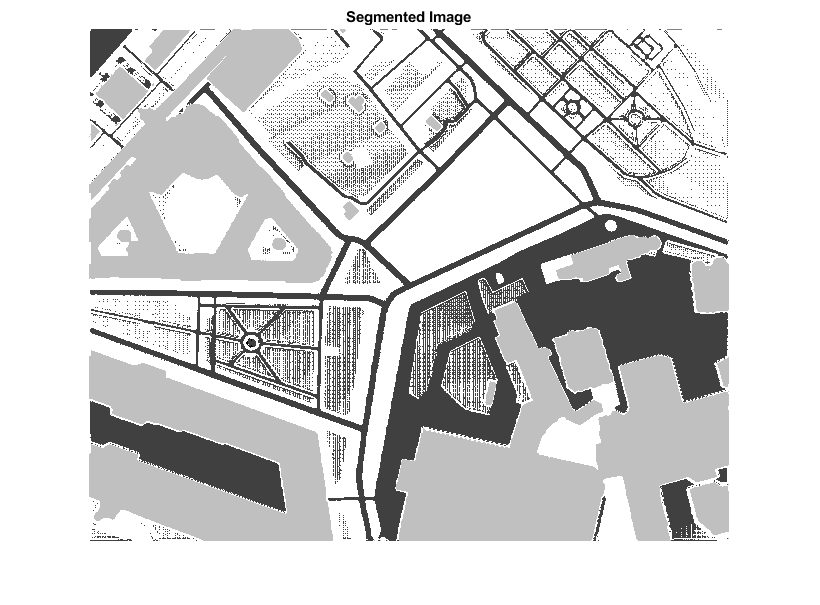

figure
imshow(segmentedImage,[])
title('Segmented Image')

The output of semantic segmentation is noisy. Perform post image processing to remove noise and stray pixels. Use the [`medfilt2`](docid:images_ref.bupa05x-1) function to remove salt-and-pepper noise from the segmentation. Visualize the segmented image with the noise removed.

% segmentedImage = medfilt2(segmentedImage,[7,7]);
% imshow(segmentedImage,[]);
% title('Segmented Image  with Noise Removed')

Overlay the segmented image on the histogram-equalized RGB validation image.

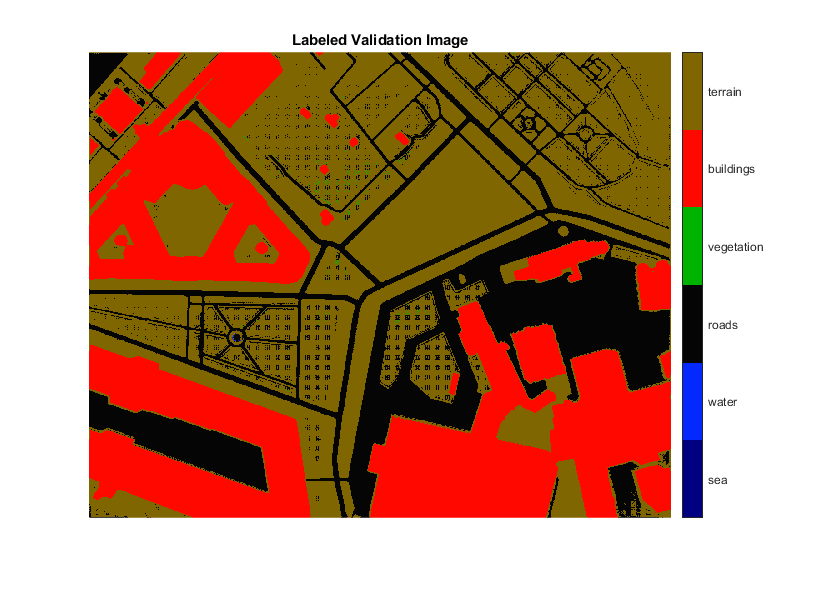

B = labeloverlay(frame(:,:,3:5),segmentedImage,'Transparency',0,'Colormap',map);
figure
imshow(B)
N = numel(classNames);
ticks = 1/(N*2):1/N:1;
title('Labeled Validation Image')
colorbar('TickLabels',cellstr(classNames),'Ticks',ticks,'TickLength',0,'TickLabelInterpreter','none');
colormap(map)

Save the segmented image and ground truth labels as PNG files. These will be used to compute accuracy metrics.

imwrite(segmentedImage,'raw_results.png');
imwrite(gtruth,'gtruth.png');
imwrite(B,'getmapped.png');

## Quantify Segmentation Accuracy

Create a [`pixelLabelDatastore`](docid:vision_ref#mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) for the segmentation results and the ground truth labels.

pxdsResults = pixelLabelDatastore('raw_results.png',classNames,pixelLabelIds);
pxdsTruth = pixelLabelDatastore('gtruth.png',classNames,pixelLabelIds);

Measure the global accuracy of the semantic segmentation by using the [`evaluateSemanticSegmentation`](docid:vision_ref.mw_ec14c36c-b93d-4fde-8512-ea7d51651b89) function.

ssm = evaluateSemanticSegmentation(pxdsResults,pxdsTruth,'Metrics','global-accuracy');

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy.
* Processed 1 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy
    ______________

       0.61945    



The global accuracy score indicates that just over 70-80% of the pixels are classified correctly.

In order to check the accuracy when segmenting an image, it will be passed onto the Finder algorithm.

## Finder

With a map previously created using Blender's nodes,

### Load map

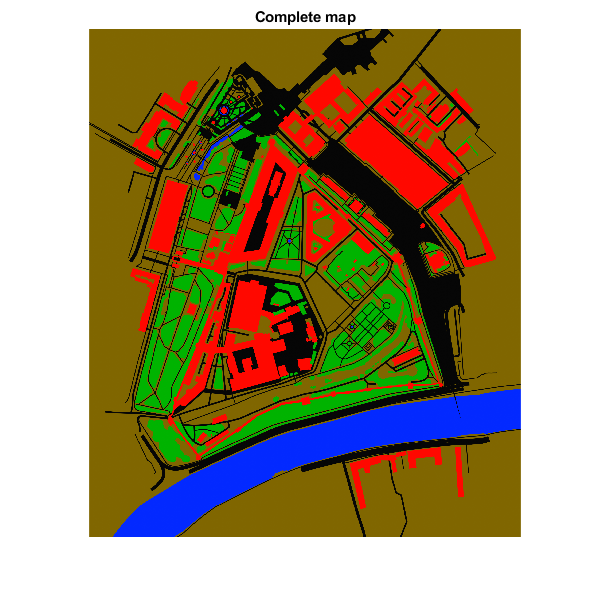

cargarImagen = true;
if cargarImagen
    sceneImage = imread('img/moscu_render_04.png');
    save mapa.mat sceneImage
else
    load mapa.mat
end
figure;
imshow(sceneImage);
title('Complete map')

### Frame manipulation

First of all, lets define a new variable called `boxImage` to operate or transform the labelled image.

boxImage = B;

Once it's loaded we can specify a scale and/or rotation in degrees to give to our frame.

scale = 1;
r = 118;

And perform the transformations.

boxImage = imresize(boxImage,scale);
boxImage = imrotate(boxImage,-r);

And plot both the original one and the transformated one.

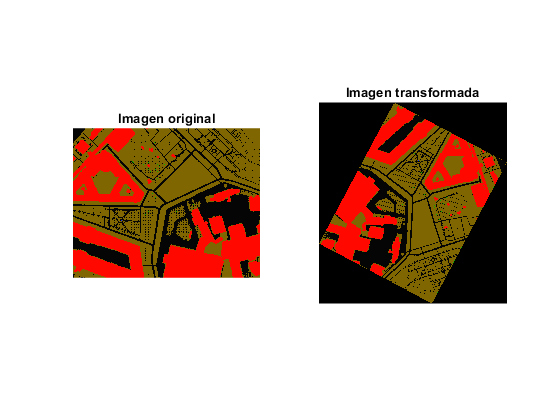

figure;
subplot(1,2,1);
imshow(B);
title('Imagen original')
subplot(1,2,2);
imshow(boxImage);
title('Imagen transformada');

In order for the SURF and MSER algorithms to work, both images must be converted to grayscale.

sceneImage = rgb2gray(sceneImage);
boxImage = rgb2gray(boxImage);

### SURF method

tic;
boxPoints = detectSURFFeatures(boxImage);
scenePoints = detectSURFFeatures(sceneImage);

After extracting SURF points from each image, they can be plotted.

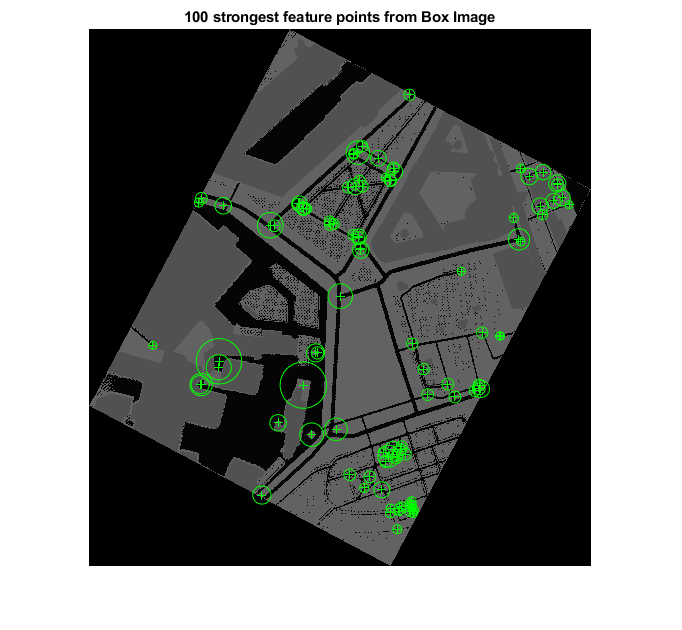

figure;
imshow(boxImage);
title('100 strongest feature points from Box Image');
hold on;
plot(selectStrongest(boxPoints,100));

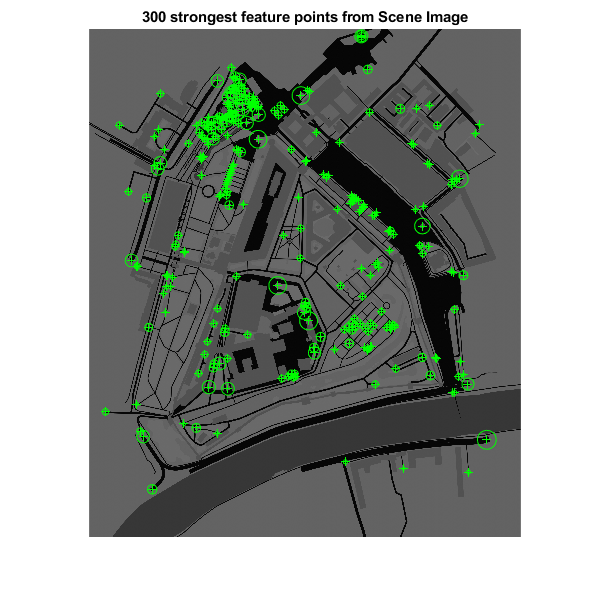


figure;
imshow(sceneImage);
title('300 strongest feature points from Scene Image');
hold on;
plot(selectStrongest(scenePoints,300));

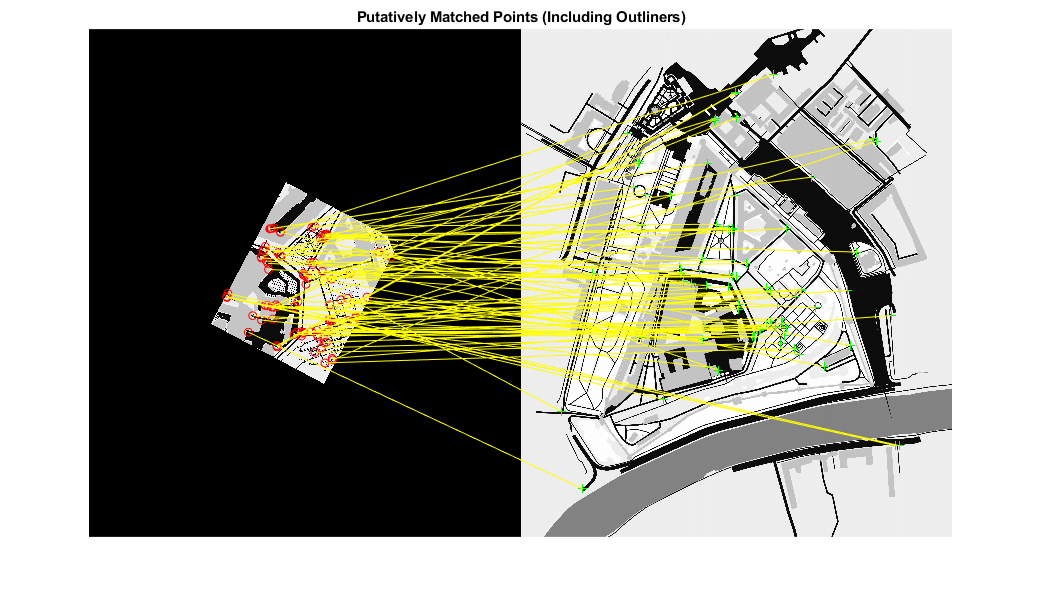


[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

boxPairs = matchFeatures(boxFeatures, sceneFeatures);

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);

figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints,...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliners)');

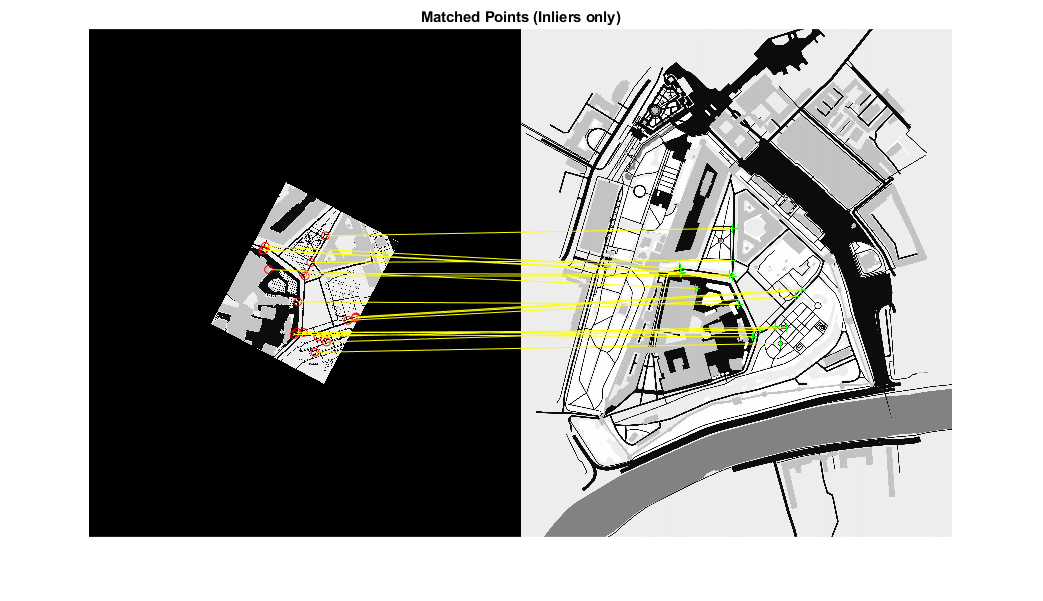


[tform, inlierBoxPoints, inlierScenePoints] = ...
    estimateGeometricTransform(matchedBoxPoints, matchedScenePoints, 'affine');


figure;
showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints,...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers only)')

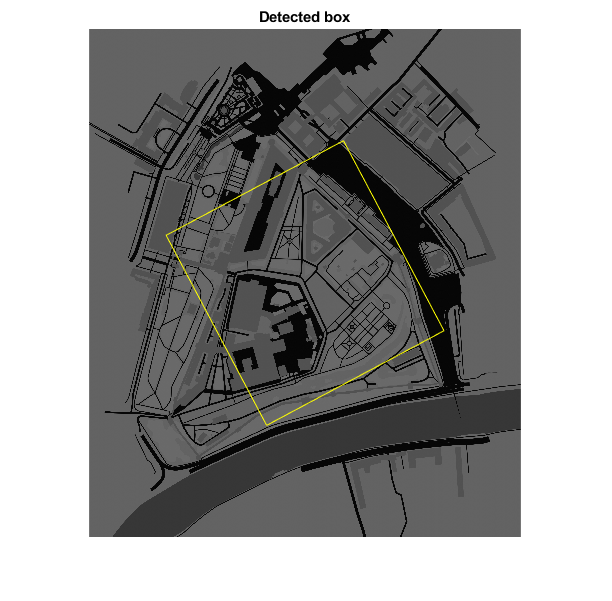


boxPolygon = [1, 1;...
    size(boxImage, 2), 1;...
    size(boxImage, 2), size(boxImage, 1);...
    1, size(boxImage, 1);...
    1, 1];
newBoxPolygon = transformPointsForward(tform, boxPolygon);

figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'y');
title('Detected box')


[y, x] = centroid(polyshape(newBoxPolygon));
y_centroid = 0.5*(max(newBoxPolygon(:,1)) + min(newBoxPolygon(:,1)));
x_centroid = 0.5* max(newBoxPolygon(:,2)) + 0.5*min(newBoxPolygon(:,2));

[heading, yaw] = headingCalculator(tform.T);

[x, y];

The heading in degrees would be:

heading

heading = single
27.9809

Since boxImage was deliberately rotated this time, we can calculate the error of the heading calculation by

heading_err = r - (heading + 90)

heading_err = single
0.0191

where it's required to add a +90 because the map is actually rotated too from the Blender export.

toc;

Elapsed time is 21.867872 seconds.


## Calculate Extent of Vegetation Cover

The final goal of this example is to calculate the extent of vegetation cover in the multispectral image. 

Find the number of pixels labeled vegetation. The label IDs 2 ("Trees"), 13 ("LowLevelVegetation"), and 14 ("Grass_Lawn") are the vegetation classes. Also find the total number of valid pixels by summing the pixels in the ROI of the mask image.

vegetationClassIds = uint8([2,13,14]);
vegetationPixels = ismember(segmentedImage(:),vegetationClassIds);
validPixels = (segmentedImage~=0);

numVegetationPixels = sum(vegetationPixels(:));
numValidPixels = sum(validPixels(:));

Calculate the percentage of vegetation cover by dividing the number of vegetation pixels by the number of valid pixels.

percentVegetationCover = (numVegetationPixels/numValidPixels)*100;
fprintf('The percentage of vegetation cover is %3.2f%%.',percentVegetationCover);

The percentage of vegetation cover is 0.01%.

## Summary

This example shows how 1to create and train a U-Net network for semantic segmentation of a seven-channel multispectral image. These are the steps to train the network:

- Download and reshape the training data.

- Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) to feed training data to the network.

- Define the layers of the U-Net network.

- Specify training options.

- Train the network using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function.

After training the U-Net network or loading a pretrained U-Net network, the example performs semantic segmentation of the validation data and measures the segmentation accuracy.

## References

[1] Kemker, R., C. Salvaggio, and C. Kanan. "High-Resolution Multispectral Dataset for Semantic Segmentation." CoRR, abs/1703.01918. 2017.

[2] Ronneberger, O., P. Fischer, and T. Brox. "U-Net: Convolutional Networks for Biomedical Image Segmentation." CoRR, abs/1505.04597. 2015.

*Copyright 2018 The MathWorks, Inc.*